In the name of allah

# Linear Control Systems

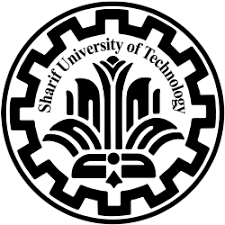

Hw 07

ali sadeghian 400101464

Fall 1402

# Theory Assignments (matalb)

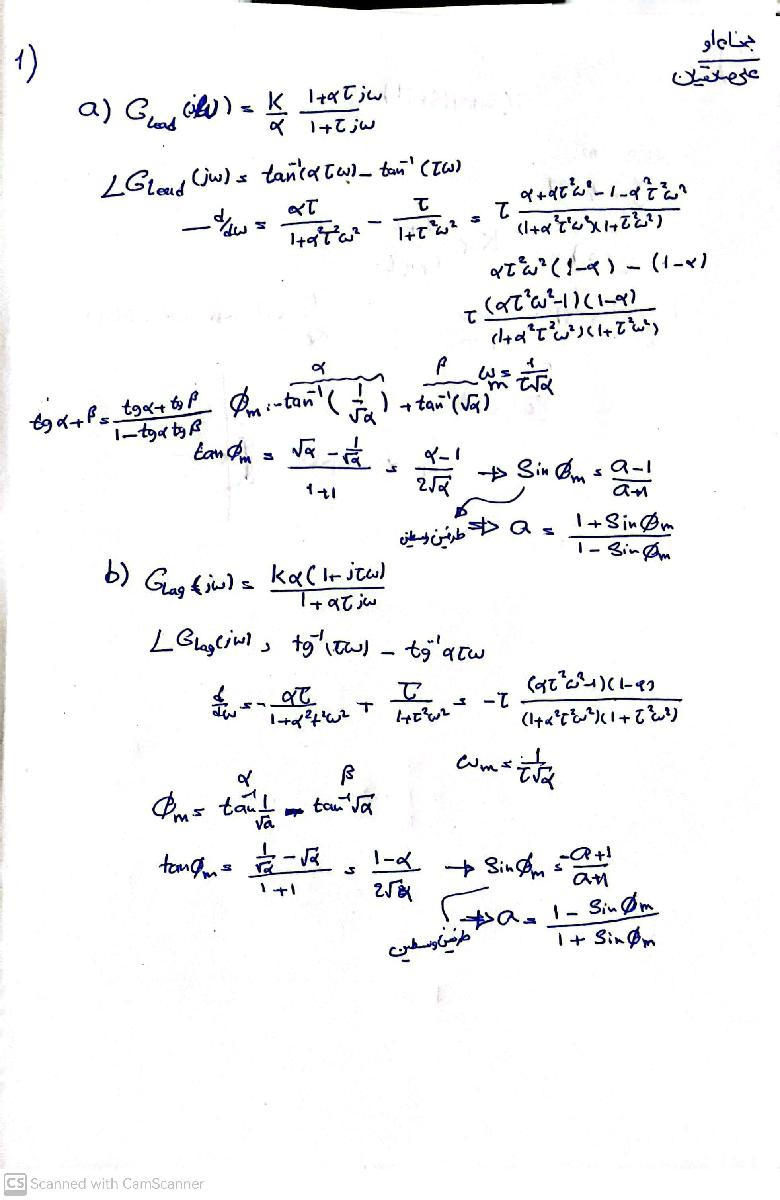

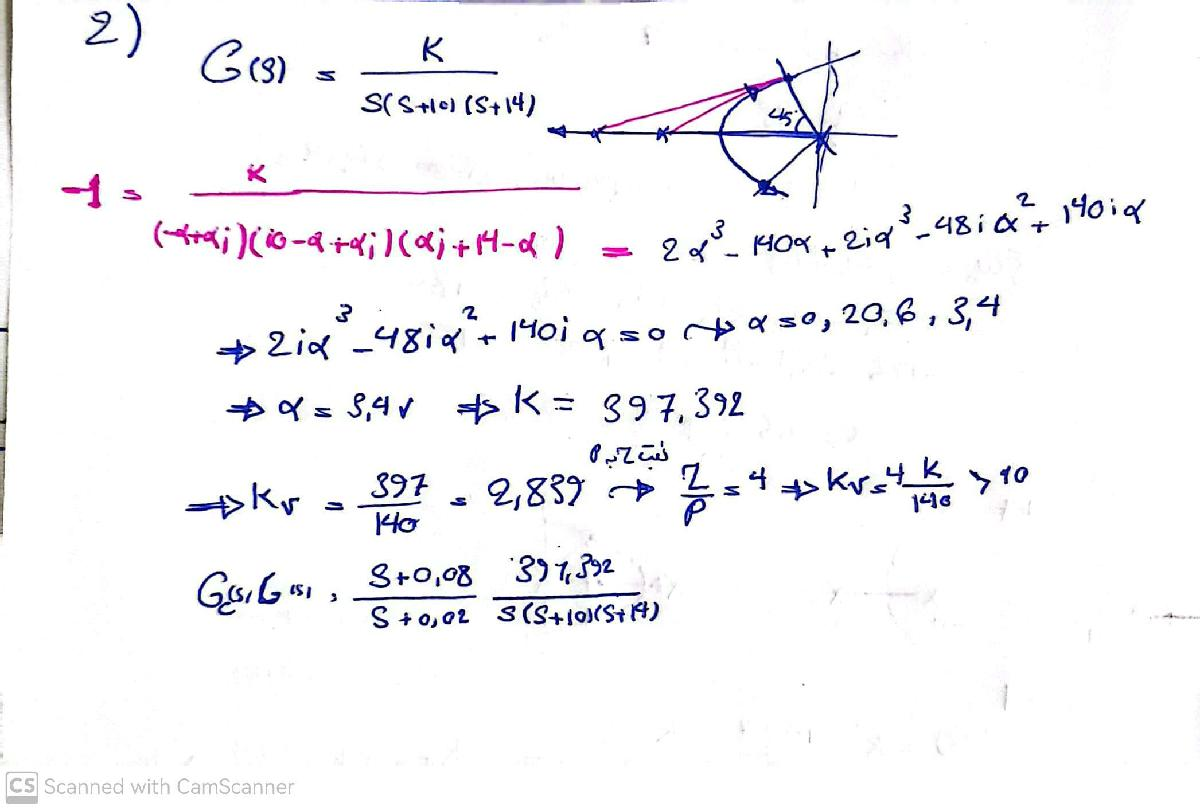

First, we draw the root locus diagram and find K so that $\zeta$ is equal to 0.707, then we find the steady-state error for that K and apply the improvement ratio to reach the desired steady-state error.

clc
clear all 
close all

# q2 provement:

num1 = [397.392];
den1 = [1 24 140 0];

num2 = [1 0.08];
den2 = [1 0.02];

sys1 = tf(num1,den1);
sys2 = tf(num2,den2);

L = sys1*sys2;

sysf = feedback(L,1)

sysf =
 
                 397.4 s + 31.79
  ---------------------------------------------
  s^4 + 24.02 s^3 + 140.5 s^2 + 400.2 s + 31.79
 
Continuous-time transfer function.



pole(sysf)

ans =  -17.1986 + 0.0000i
  -3.3698 + 3.3548i
  -3.3698 - 3.3548i
  -0.0818 + 0.0000i



$$\zeta =0\ldotp 707\Rightarrow -\zeta \omega_n =\omega_n \sqrt{1-\zeta^{2\;} }:-\left(-3\ldotp 3698\right)\approx 3\ldotp 3548\;$$


zero(sysf)

ans = -0.0800

step(sysf)
grid minor
stepinfo(sysf)

ans = struct with fields:
         RiseTime: 0.4547
    TransientTime: 1.6927
     SettlingTime: 1.6927
      SettlingMin: 0.9094
      SettlingMax: 1.0622
        Overshoot: 6.2232
       Undershoot: 0
             Peak: 1.0622
         PeakTime: 1.0113


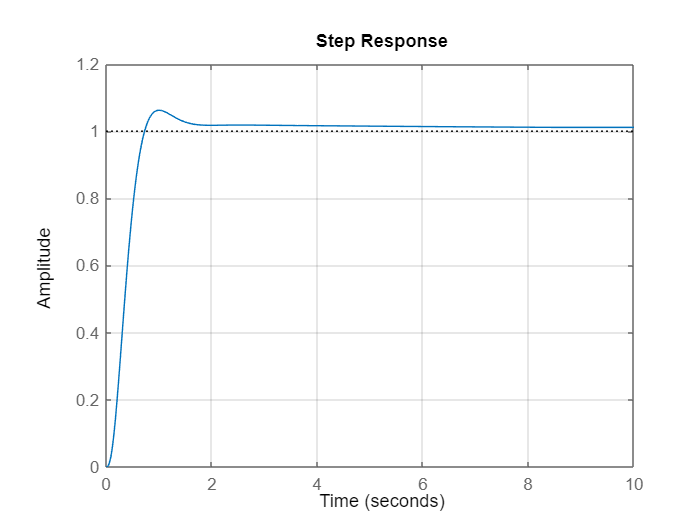

xlim([0 10])

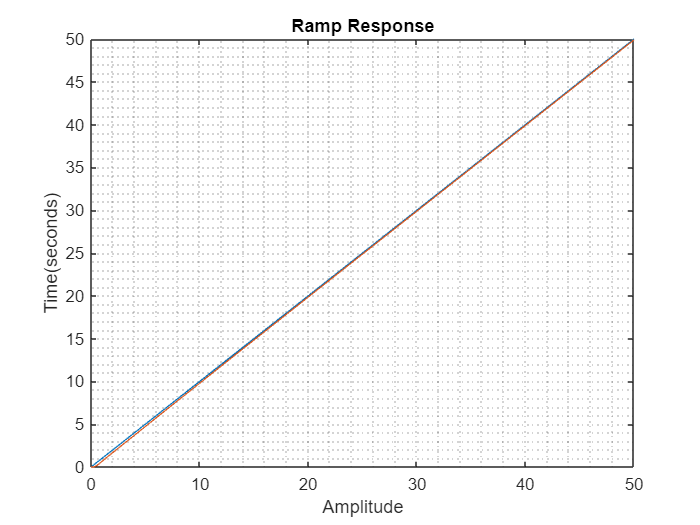

t = linspace(0,50,10001);
syms x
Ramp = x;
ramp = eval(subs(Ramp,x,t));
yt = lsim(sysf,ramp,t);
erorr = ramp-yt';
plot(t,ramp,t,yt)
title("Ramp Response")
xlabel("Amplitude")
ylabel("Time(seconds)") 
grid minor

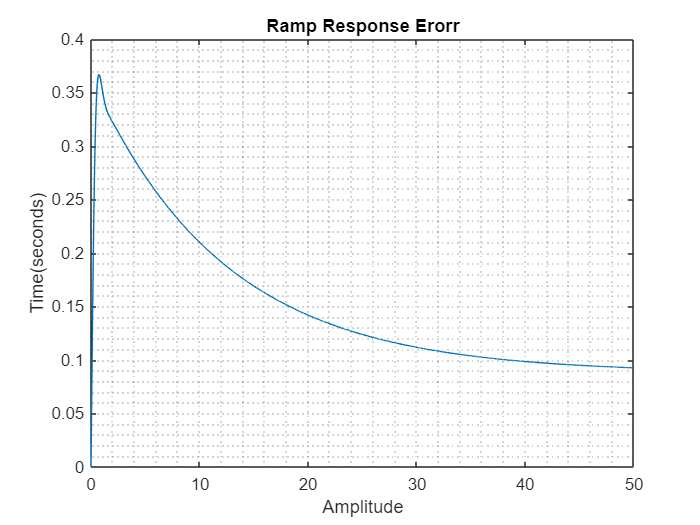

plot(t,erorr)
title("Ramp Response Erorr")
xlabel("Amplitude")
ylabel("Time(seconds)") 
grid minor

as we see, the erorr is less than 0.1.

# Q3:

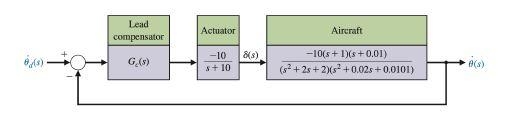


$$\begin{array}{l}
{\;\;T}_{s\;} \le 2\;\;,\;P\ldotp O\ldotp \le 30:\\
\zeta =0\ldotp 5:P\ldotp O\ldotp =15%\Rightarrow \;\zeta =\frac{\textrm{PM}}{100}\;\;:\;\textrm{PM}=50\deg \\
\;\frac{\omega_{\textrm{B3db}} }{\omega_n }=-1\ldotp 19\zeta +1\ldotp 85\;,T_{S\;} =\frac{4}{\zeta \omega_n }:\;\omega_{\textrm{B3db}} =5\;\Rightarrow \omega_n =4\;,T_s =2_s 
\end{array}$$


s = tf("s");

Actuator = (-10)/(s+10);
Aircraft = (-10)*(s+1)*(s+0.01)/(s^2+2*s+2)/(s^2+0.02*s+0.0101);
sys = Actuator*Aircraft

sys =
 
                     100 s^2 + 101 s + 1
  ----------------------------------------------------------
  s^5 + 12.02 s^4 + 22.25 s^3 + 20.56 s^2 + 0.6222 s + 0.202
 
Continuous-time transfer function.



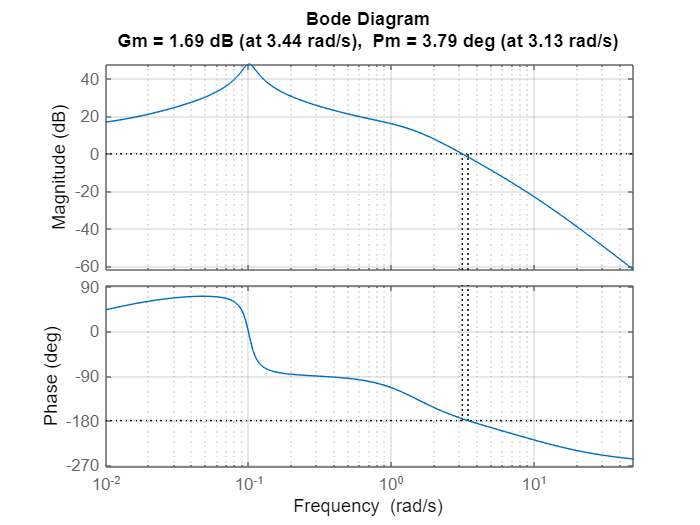

margin(sys)
grid minor
xlim([1e-2 5e1])


$$\begin{array}{l}
K^{\prime } =1\;,\;\textrm{steady}\;\textrm{state}\;\textrm{erorr}\;\textrm{ignored}\;\ldotp \\
\phi_{m\;} =50:\frac{-1+a}{1+a}=\sin \left(60\right)\Rightarrow a=13\ldotp 93\;,K={\textrm{aK}}^{\prime } \\
\omega_m :20\log \left(|G\left(j\omega |\right)\right)=-10\log \left(a\right)=-11\ldotp 44\Rightarrow \omega_m =5\ldotp 725\\
P=\omega_m \sqrt{a}=21\ldotp 367\;,Z=\frac{P}{a}=1\ldotp 534
\end{array}$$


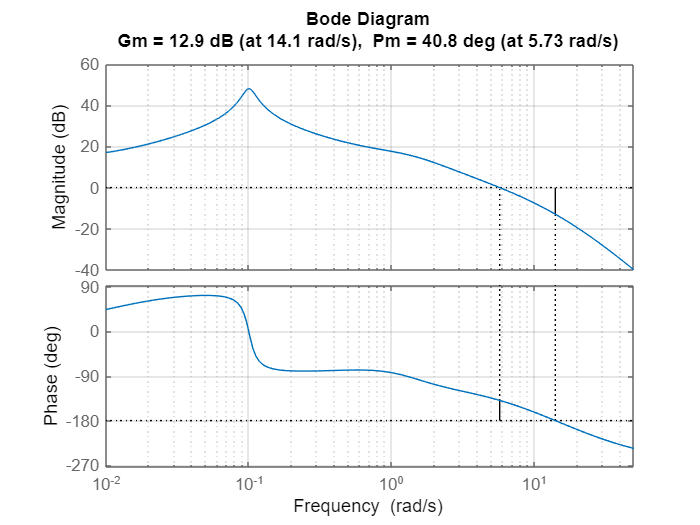

Gc = 1*(1/1.534*s+1)/(1/21.367*s+1);
sysm = sys*Gc;
margin(sysm)
grid minor
xlim([1e-2 5e1])

sysf = feedback(sysm,1);
stepinfo(sysf)

ans = struct with fields:
         RiseTime: 0.1746
    TransientTime: 192.4210
     SettlingTime: 192.4210
      SettlingMin: 0.7673
      SettlingMax: 1.2772
        Overshoot: 53.5185
       Undershoot: 0
             Peak: 1.2772
         PeakTime: 0.4960


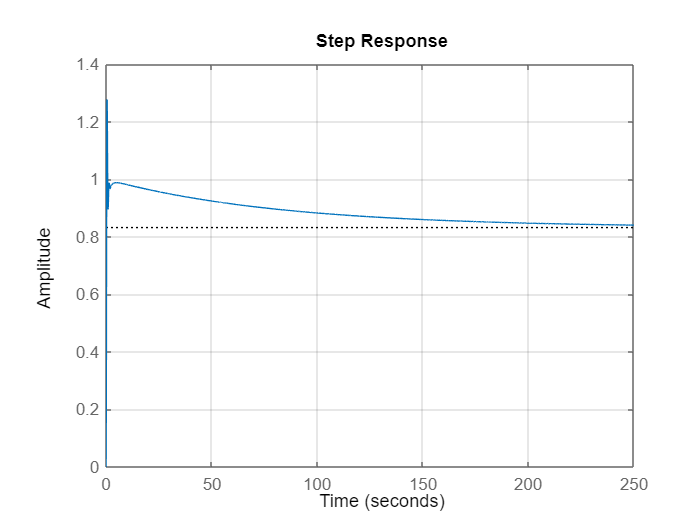

step(sysf)
grid minor

It isn't good, Let's try again.


$$\begin{array}{l}
K^{\prime } =1\;,\;\textrm{steady}\;\textrm{state}\;\textrm{erorr}\;\textrm{ignored}\;\ldotp \\
\phi_{m\;} =50:\frac{-1+a}{1+a}=\sin \left(80\right)\Rightarrow a=140\;,K={\textrm{aK}}^{\prime } \\
\omega_m :20\log \left(|G\left(j\omega |\right)\right)=-10\log \left(a\right)=-21\ldotp 46\Rightarrow \omega_m =9\ldotp 33\\
P=\omega_m \sqrt{a}=110\ldotp 4\;,Z=\frac{P}{a}=0\ldotp 789
\end{array}$$


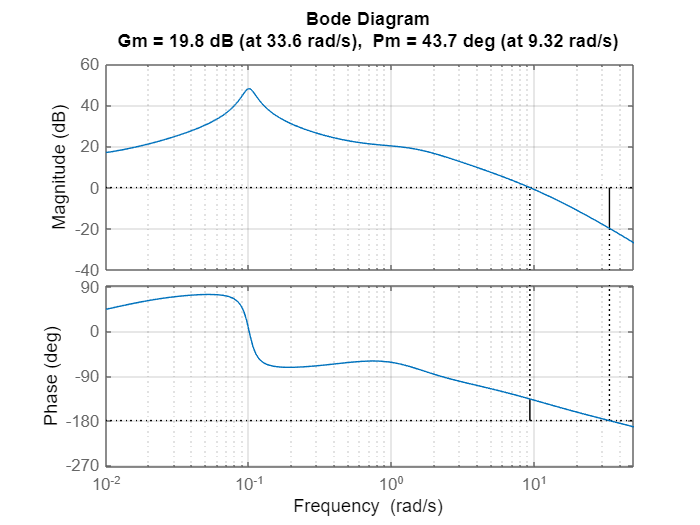

Gc = 1*(1/0.789*s+1)/(1/110.4*s+1);
sysm = sys*Gc;
margin(sysm)
grid minor
xlim([1e-2 5e1])

Tout = linspace(0,10,1001);
sysf = feedback(sysm,1);
[Yout,Tout] = step(sysf,Tout);
stepinfo(sysf)

ans = struct with fields:
         RiseTime: 0.1307
    TransientTime: 0.7900
     SettlingTime: 0.7900
      SettlingMin: 0.8956
      SettlingMax: 1.2222
        Overshoot: 25.4132
       Undershoot: 0
             Peak: 1.2222
         PeakTime: 0.3096


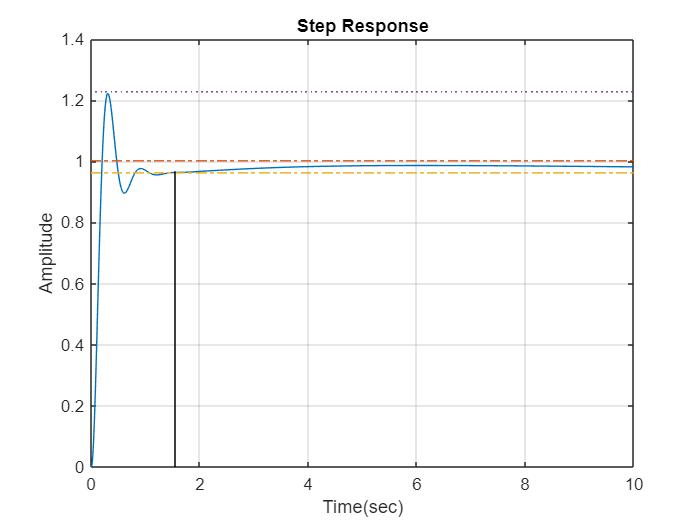

u = Step(Tout);
plot(Tout,Yout,Tout,u*1.02*0.98175,'-.',Tout,u*0.98*0.98175,'-.',Tout,u*1.25*0.98175,':');
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
annotation('line',[0.25 0.25],[0.11 0.6738])
grid on

as we see, T<2 and P.O. is less than 30%

# Q4)

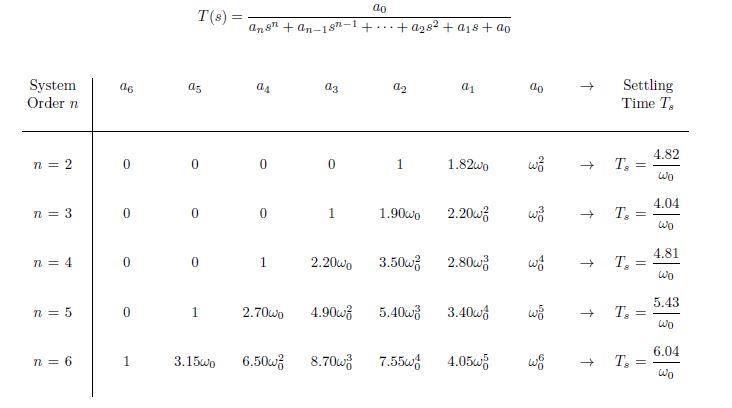

s =tf("s");

w2 = 4.82;
G2 = (w2^2)/(s^2 + 1.82*w2*s + w2^2);

w3 = 4.04;
G3 = (w3^3)/(s^3+1.9*w3*s^2 + 2.2*w3^2*s + w3^3);

w4 = 4.81;
G4 = (w4^4)/(s^4+2.2*w4*s^3+3.5*w4^2*s^2 + 2.8*w4^3*s + w4^4);

w5 = 5.43;
G5 = (w5^5)/(s^5+2.7*w5*s^4+4.9*w5^2*s^3+5.4*w5^3*s^2 + 3.4*w5^4*s + w5^5);

w6 = 6.04;
G6 = (w6^6)/(s^6+3.15*w6*s^5+6.5*w6^2*s^4+8.7*w6^3*s^3+7.55*w6^4*s^2 + 4.05*w6^5*s + w6^6);

## a)


$$T_{s\;} =1:\omega_0 =a\;\;\;\;\left(a=4\ldotp 82,4\ldotp 04,4\ldotp 81,5\ldotp 43,6\ldotp 04\right)$$


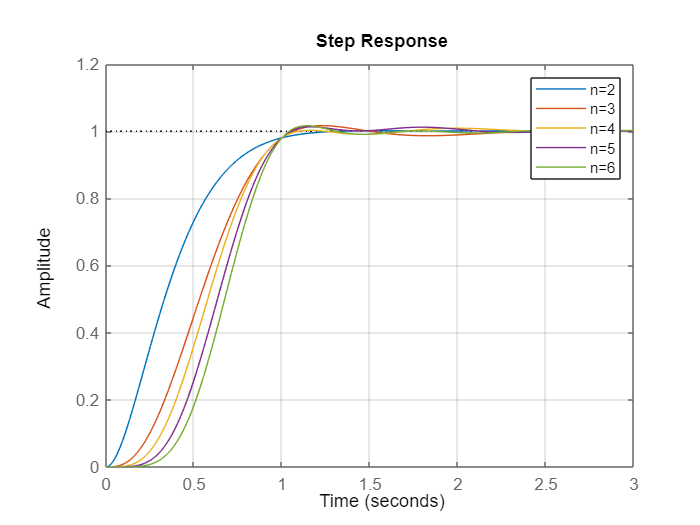

step(G2,G3,G4,G5,G6)
grid minor
legend("n=2","n=3","n=4","n=5","n=6")

g2 =stepinfo(G2)

g2 = struct with fields:
         RiseTime: 0.6076
    TransientTime: 0.9977
     SettlingTime: 0.9977
      SettlingMin: 0.9041
      SettlingMax: 1.0010
        Overshoot: 0.1012
       Undershoot: 0
             Peak: 1.0010
         PeakTime: 1.5749


g3 =stepinfo(G3)

g3 = struct with fields:
         RiseTime: 0.6092
    TransientTime: 0.9992
     SettlingTime: 0.9992
      SettlingMin: 0.9098
      SettlingMax: 1.0165
        Overshoot: 1.6510
       Undershoot: 0
             Peak: 1.0165
         PeakTime: 1.2259


g4 =stepinfo(G4)

g4 = struct with fields:
         RiseTime: 0.5476
    TransientTime: 0.9985
     SettlingTime: 0.9985
      SettlingMin: 0.9079
      SettlingMax: 1.0088
        Overshoot: 0.8846
       Undershoot: 0
             Peak: 1.0088
         PeakTime: 1.9974


g5 =stepinfo(G5)

g5 = struct with fields:
         RiseTime: 0.5110
    TransientTime: 0.9988
     SettlingTime: 0.9988
      SettlingMin: 0.9133
      SettlingMax: 1.0129
        Overshoot: 1.2853
       Undershoot: 0
             Peak: 1.0129
         PeakTime: 1.1548


g6 =stepinfo(G6)

g6 = struct with fields:
         RiseTime: 0.4763
    TransientTime: 0.9996
     SettlingTime: 0.9996
      SettlingMin: 0.9143
      SettlingMax: 1.0163
        Overshoot: 1.6257
       Undershoot: 0
             Peak: 1.0163
         PeakTime: 1.1419


By increasing the order of the filter, the system becomes faster because the bandwidth of the filter is increase and the riseing time is reduced, but in the initial , we have lag for high order filters.

## b)

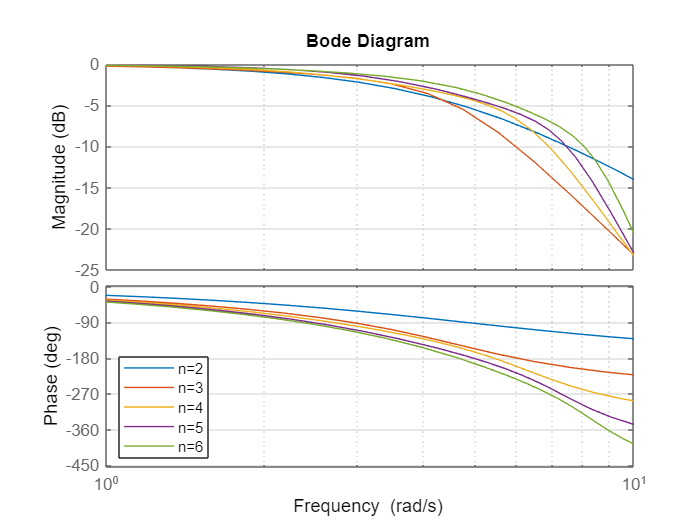

bode(G2,G3,G4,G5,G6)
grid minor
legend("n=2","n=3","n=4","n=5","n=6",'Location','southwest')
xlim([1e0 1e1])

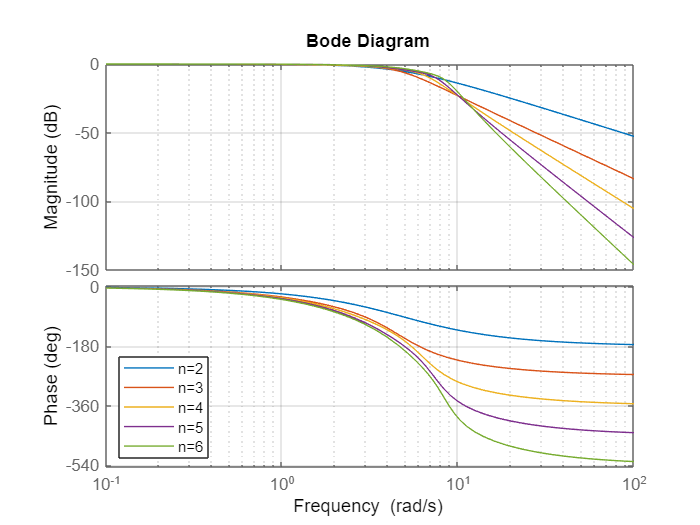

bode(G2,G3,G4,G5,G6)
grid minor
legend("n=2","n=3","n=4","n=5","n=6",'Location','southwest')
xlim([1e-1 1e2])

As mentioned in the previous section, the bandwidth increases with the increase of the order of the filter and makes the system faster.

# Q5)

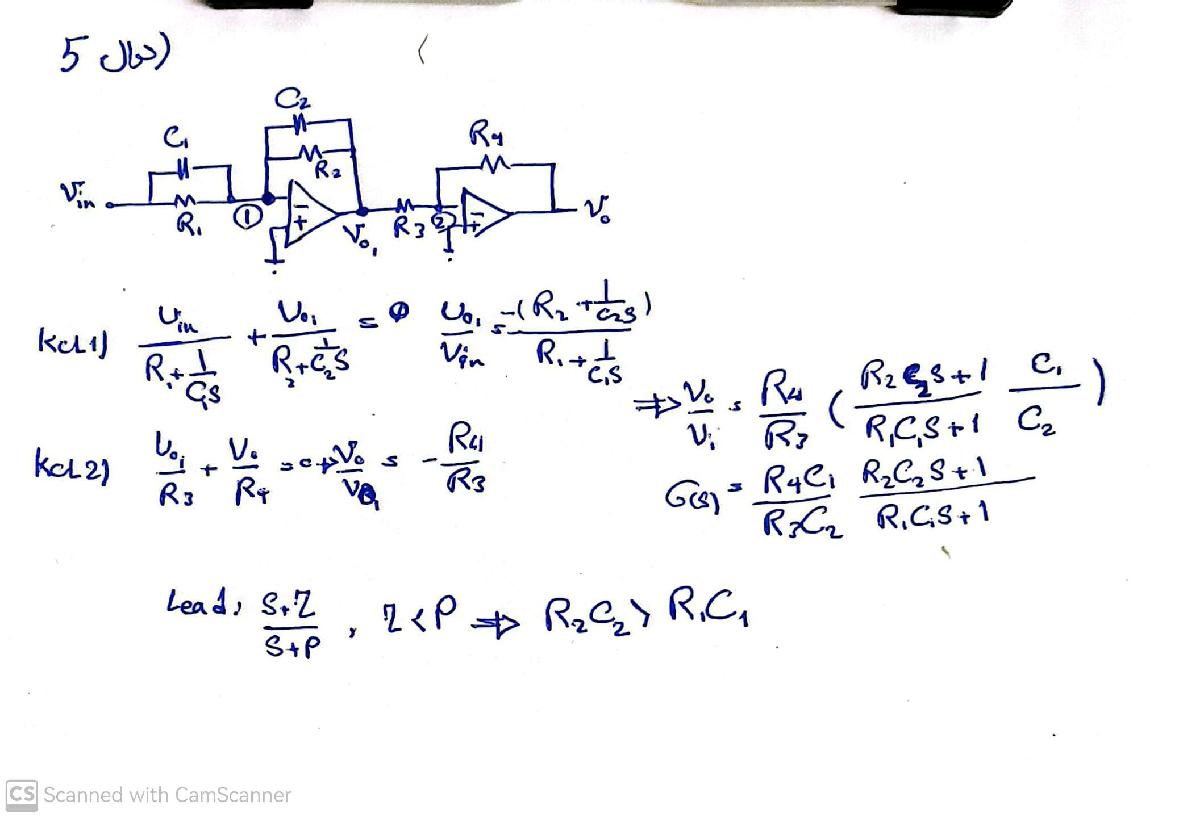

# Q6)

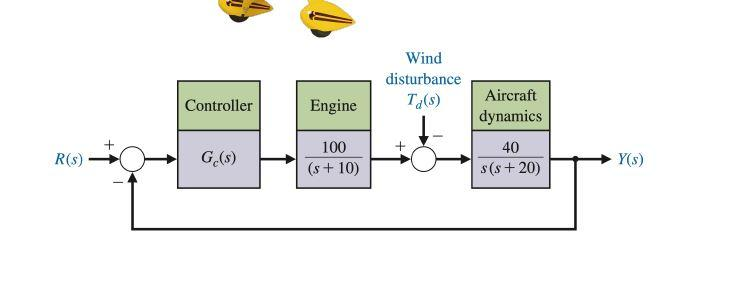

## a)


$$\begin{array}{l}
\left({{-G}_c \textrm{EY}-T}_d \right)A=Y\Rightarrow \frac{Y}{T_d }=\frac{-A}{G_c \textrm{EA}+1}=\frac{-\frac{40}{s\left(s+20\right)}}{\frac{4000}{s\left(s+10\right)\left(s+20\right)}G_c \left(s\right)+1}=\frac{-40\left(s+10\right)}{4000G_c \left(s\right)+s\left(s+10\right)\left(s+20\right)}\\
y\left(\infty \right)\;=|\frac{-400}{4000G_c \left(0\right)}|\le 0\ldotp 05\;,G_c \left(s\right)=K\ge 2
\end{array}$$


## b)


$$\begin{array}{l}
K=2:\\
L\left(s\right)=2\;\frac{100}{s+10}\frac{40}{s\left(s+20\right)}=\frac{8000}{s\left(s+10\right)\left(s+20\right)}\Rightarrow \frac{L\left(s\right)}{1+L\left(s\right)}=\frac{8000}{s\left(s+10\right)\left(s+20\right)+8000}\;\\
\Rightarrow p=0\ldotp 8316\pm 15\ldotp 8735i\;,-31\ldotp 6631\\
\textrm{system}\;{\textrm{isn}}^{\prime } t\;\textrm{stable}
\end{array}$$


s =tf("s");
E = 100/(s+10);
A = 40/s/(s+20);
sys = E*A;
sysf = feedback(2*sys,1)

sysf =
 
             8000
  ---------------------------
  s^3 + 30 s^2 + 200 s + 8000
 
Continuous-time transfer function.



pole(sysf)

ans =  -31.6631 + 0.0000i
   0.8316 +15.8735i
   0.8316 -15.8735i


## c)

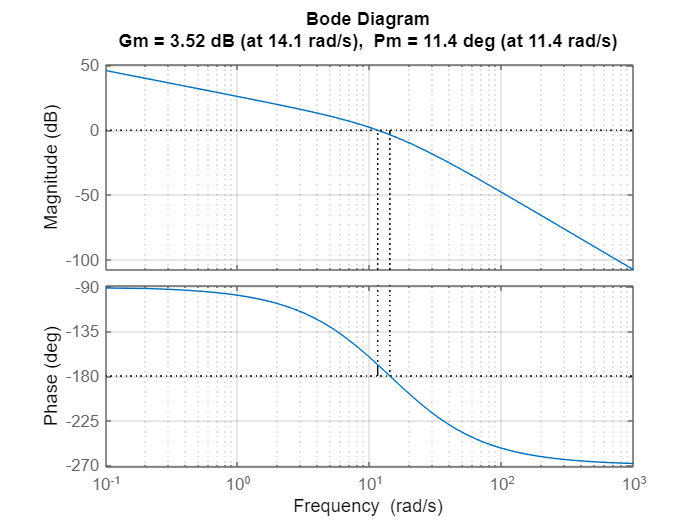

margin(sys)
grid minor

sys

sys =
 
          4000
  --------------------
  s^3 + 30 s^2 + 200 s
 
Continuous-time transfer function.




$$\begin{array}{l}
K^{\prime } =1:\;\;\textrm{steady}\;\textrm{erorr}\;\textrm{is}\;0\\
\phi_{m\;\;} =30:\Delta \phi_{m\;} =20\Rightarrow \frac{a-1}{a+1}=\sin \left(45\right)\Rightarrow a=5\ldotp 828,K=a\\
\omega_m =20\log |G\left(j\omega \right)|=-10\log \left(a\right)=-7\ldotp 66\Rightarrow \omega_{m\;} =18\\
p=\omega_m \sqrt{a}=41\ldotp 36\;,z=\frac{p}{a}=7\ldotp 834
\end{array}$$


Gc1 = (1/7.834*s+1)/(1/41.36*s+1)

Gc1 =
 
  0.1276 s + 1
  -------------
  0.02418 s + 1
 
Continuous-time transfer function.



sysm1 = sys*Gc1 

sysm1 =
 
                510.6 s + 4000
  -------------------------------------------
  0.02418 s^4 + 1.725 s^3 + 34.84 s^2 + 200 s
 
Continuous-time transfer function.



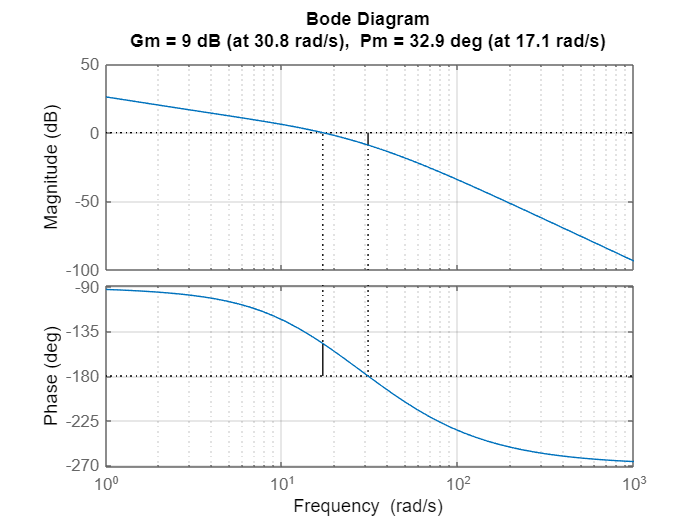

margin(sysm1)
grid minor

## d)

margin(sysm1)
grid minor

sysm1

sysm1 =
 
                510.6 s + 4000
  -------------------------------------------
  0.02418 s^4 + 1.725 s^3 + 34.84 s^2 + 200 s
 
Continuous-time transfer function.




$$\begin{array}{l}
K^{\prime } =0\ldotp 8:\;\;\textrm{steady}\;\textrm{erorr}\;\textrm{is}\;0\\
\phi_{m\;\;} =55:\Delta \phi_{m\;} =25\Rightarrow \frac{a-1}{a+1}=\sin \left(40\right)\Rightarrow a=5,K=0\ldotp 8\;a=4\\
\omega_m =20\log |G\left(j\omega \right)|=-10\log \left(a\right)=-4\ldotp 77\Rightarrow \omega_{m\;} =27\ldotp 5\\
p=\omega_m \sqrt{a}=61\ldotp 5\;,z=\frac{p}{a}=12\ldotp 3
\end{array}$$


Gc2 = 0.8*(1/12.3*s+1)/(1/67.5*s+1)

Gc2 =
 
  0.06504 s + 0.8
  ---------------
   0.01481 s + 1
 
Continuous-time transfer function.



sysm2 = sysm1*Gc2

sysm2 =
 
                  33.21 s^2 + 668.6 s + 3200
  ----------------------------------------------------------
  0.0003582 s^5 + 0.04974 s^4 + 2.241 s^3 + 37.8 s^2 + 200 s
 
Continuous-time transfer function.



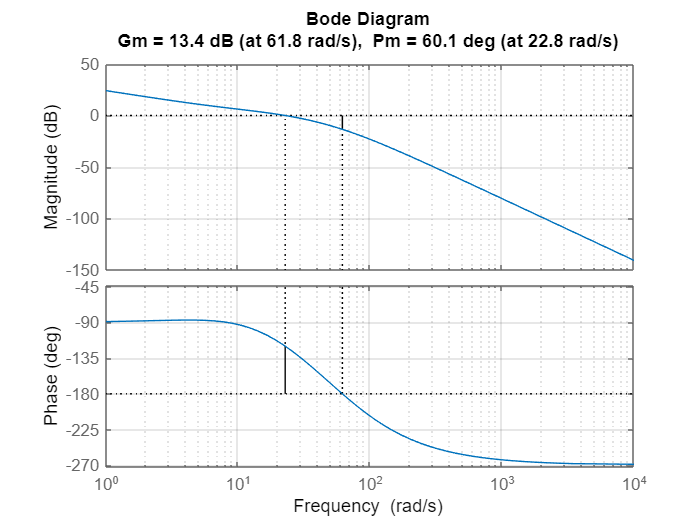

margin(sysm2)
grid minor

## e)

sysm2

sysm2 =
 
                  33.21 s^2 + 668.6 s + 3200
  ----------------------------------------------------------
  0.0003582 s^5 + 0.04974 s^4 + 2.241 s^3 + 37.8 s^2 + 200 s
 
Continuous-time transfer function.



sysm1

sysm1 =
 
                510.6 s + 4000
  -------------------------------------------
  0.02418 s^4 + 1.725 s^3 + 34.84 s^2 + 200 s
 
Continuous-time transfer function.



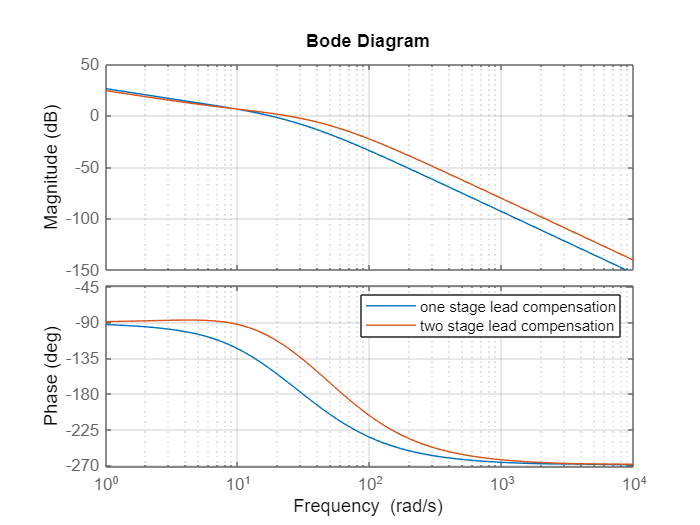

bode(sysm1,sysm2)
grid minor
legend("one stage lead compensation","two stage lead compensation")

As expected, the bandwidth increases with the addition of the lead-phase compensator.

## f)

To have zero effect on the output, we need to put an integrator, my suggestion is PI:


$$\begin{array}{l}
\left({{-G}_c \textrm{EY}-T}_d \right)A=Y\Rightarrow \frac{Y}{T_d }=\frac{-A}{G_c \textrm{EA}+1}=\frac{-\frac{40}{s\left(s+20\right)}}{\frac{4000}{s\left(s+10\right)\left(s+20\right)}G_c \left(s\right)+1}=\frac{-40\left(s+10\right)}{4000G_c \left(s\right)+s\left(s+10\right)\left(s+20\right)}\\
y\left(\infty \right)\;=|\frac{-400}{4000G_c \left(0\right)}|\le 0\ldotp 05:G_c \left(s\right)=k\frac{\textrm{ps}+1}{s}\Rightarrow y\left(\infty \right)=0
\end{array}$$


## 
$$L\left(s\right)=k\frac{\textrm{ps}+1}{s}\;\frac{100}{s+10}\frac{40}{s\left(s+20\right)}=\frac{8000k\left(\textrm{ps}+1\right)}{s^2 \left(s+10\right)\left(s+20\right)}\Rightarrow \frac{L\left(s\right)}{1+L\left(s\right)}=\frac{8000k\left(\textrm{ps}+1\right)}{s^2 \left(s+10\right)\left(s+20\right)+8000k\left(\textrm{ps}+1\right)}\;$$


sys

sys =
 
          4000
  --------------------
  s^3 + 30 s^2 + 200 s
 
Continuous-time transfer function.



Gc3 = 0.2*(1*s+1)/s

Gc3 =
 
  0.2 s + 0.2
  -----------
       s
 
Continuous-time transfer function.



sysf3=feedback(sys*Gc3,1);
pole(sysf3)

ans =  -22.6642 + 0.0000i
  -2.9758 + 4.0801i
  -2.9758 - 4.0801i
  -1.3841 + 0.0000i


It is stable

## g)

Step response (r(t) is input)

sysf1=feedback(sysm1,1)

sysf1 =
 
                     510.6 s + 4000
  ----------------------------------------------------
  0.02418 s^4 + 1.725 s^3 + 34.84 s^2 + 710.6 s + 4000
 
Continuous-time transfer function.



sysf2=feedback(sysm2,1)

sysf2 =
 
                       33.21 s^2 + 668.6 s + 3200
  --------------------------------------------------------------------
  0.0003582 s^5 + 0.04974 s^4 + 2.241 s^3 + 71.01 s^2 + 868.6 s + 3200
 
Continuous-time transfer function.



sysf3

sysf3 =
 
              800 s + 800
  ------------------------------------
  s^4 + 30 s^3 + 200 s^2 + 800 s + 800
 
Continuous-time transfer function.



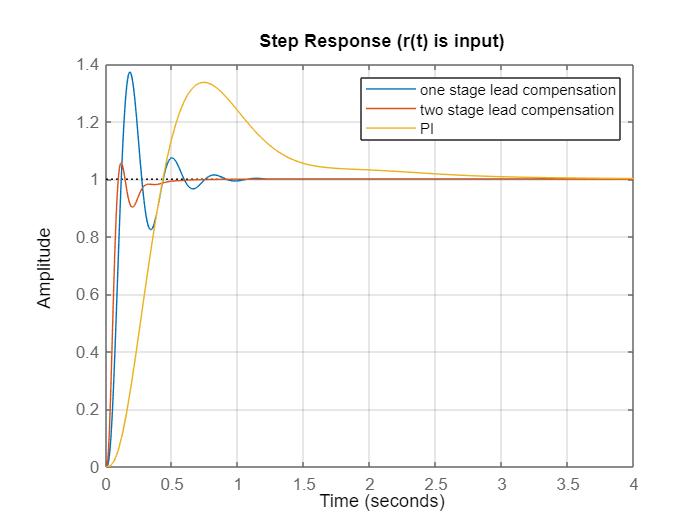

step(sysf1,sysf2,sysf3)
grid minor
title("Step Response (r(t) is input)")
legend("one stage lead compensation","two stage lead compensation","PI")
grid minor

As we can see, the overshoot for the second-order compensated system is less than the others, and its settling time is also very short, the PI controller overshoot is less than the first-order compensator, because a pole near the imag axis is added to the total, and this is what makes it slow. In the following, the disturbance response of the systems is also reported

stepinfo(sysf1)

ans = struct with fields:
         RiseTime: 0.0703
    TransientTime: 0.7091
     SettlingTime: 0.7091
      SettlingMin: 0.8244
      SettlingMax: 1.3719
        Overshoot: 37.1940
       Undershoot: 0
             Peak: 1.3719
         PeakTime: 0.1803


stepinfo(sysf2)

ans = struct with fields:
         RiseTime: 0.0567
    TransientTime: 0.3000
     SettlingTime: 0.3000
      SettlingMin: 0.9013
      SettlingMax: 1.0566
        Overshoot: 5.6551
       Undershoot: 0
             Peak: 1.0566
         PeakTime: 0.1145


stepinfo(sysf3)

ans = struct with fields:
         RiseTime: 0.2749
    TransientTime: 2.4379
     SettlingTime: 2.4379
      SettlingMin: 0.9299
      SettlingMax: 1.3365
        Overshoot: 33.6469
       Undershoot: 0
             Peak: 1.3365
         PeakTime: 0.7428



$$\left({{-G}_c \textrm{EY}-T}_d \right)A=Y\Rightarrow \frac{Y}{T_d }=\frac{-A}{G_c \textrm{EA}+1}$$


Step response (T(t) is input)

sys1 = -A/(Gc1*E*A+1)

sys1 =
 
                -0.9671 s^4 - 69.01 s^3 - 1393 s^2 - 8000 s
  -----------------------------------------------------------------------
  0.02418 s^6 + 2.209 s^5 + 69.34 s^4 + 1407 s^3 + 1.821e04 s^2 + 80000 s
 
Continuous-time transfer function.



sys2 = -A/(Gc2*E*A+1)

sys2 =
 
               -0.5926 s^4 - 57.78 s^3 - 1319 s^2 - 8000 s
  ----------------------------------------------------------------------
  0.01481 s^6 + 1.741 s^5 + 61.85 s^4 + 1119 s^3 + 1.24e04 s^2 + 64000 s
 
Continuous-time transfer function.



sys3 = -A/(Gc3*E*A+1)

sys3 =
 
               -40 s^4 - 1200 s^3 - 8000 s^2
  -------------------------------------------------------
  s^6 + 50 s^5 + 800 s^4 + 4800 s^3 + 16800 s^2 + 16000 s
 
Continuous-time transfer function.



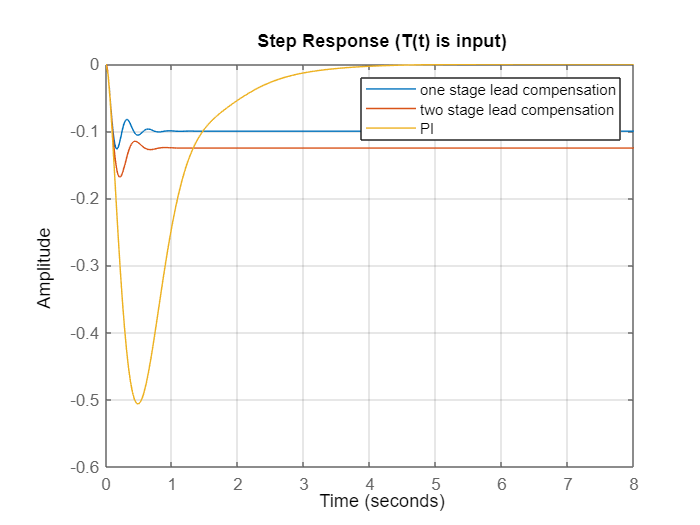

step(sys1,sys2,sys3)
grid minor
title("Step Response (T(t) is input)")
legend("one stage lead compensation","two stage lead compensation","PI")

stepinfo(sys1)

ans = struct with fields:
         RiseTime: 0.0721
    TransientTime: 0.6864
     SettlingTime: 0.6864
      SettlingMin: -0.1265
      SettlingMax: -0.0826
        Overshoot: 26.5250
       Undershoot: 0
             Peak: 0.1265
         PeakTime: 0.1615


stepinfo(sys2)

ans = struct with fields:
         RiseTime: 0.0833
    TransientTime: 0.5513
     SettlingTime: 0.5513
      SettlingMin: -0.1684
      SettlingMax: -0.1139
        Overshoot: 34.7347
       Undershoot: 0
             Peak: 0.1684
         PeakTime: 0.2096


stepinfo(sys3)

ans = struct with fields:
         RiseTime: 0
    TransientTime: 3.1920
     SettlingTime: NaN
      SettlingMin: -0.5061
      SettlingMax: 0
        Overshoot: Inf
       Undershoot: Inf
             Peak: 0.5061
         PeakTime: 0.4952


# MATLAB Assignments

clc
close all
clear all

# 7 PID Tuner Toolbox

## a)   $\frac{1}{10s+1}$

sys = tf([1],[10 1]);

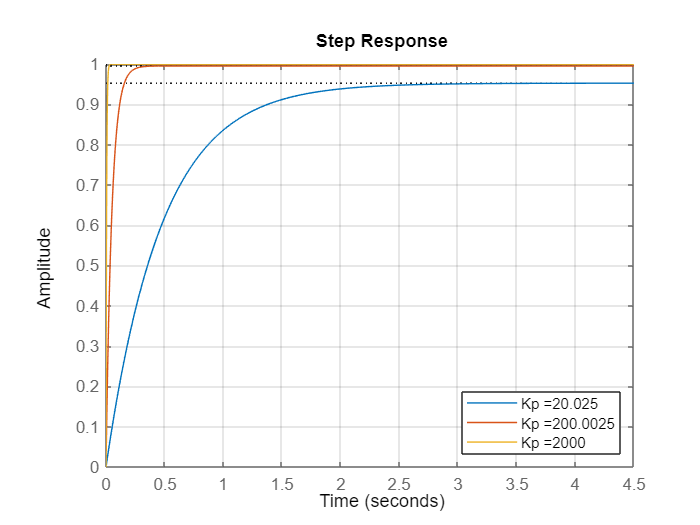

sysf1 = feedback(sys*P1,1);
sysf2 = feedback(sys*P2,1);
sysf3 = feedback(sys*P3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+P1.Kp,"Kp ="+P2.Kp,"Kp ="+P3.Kp,'Location','southeast')
grid minor

Everything gets better as kp increases.

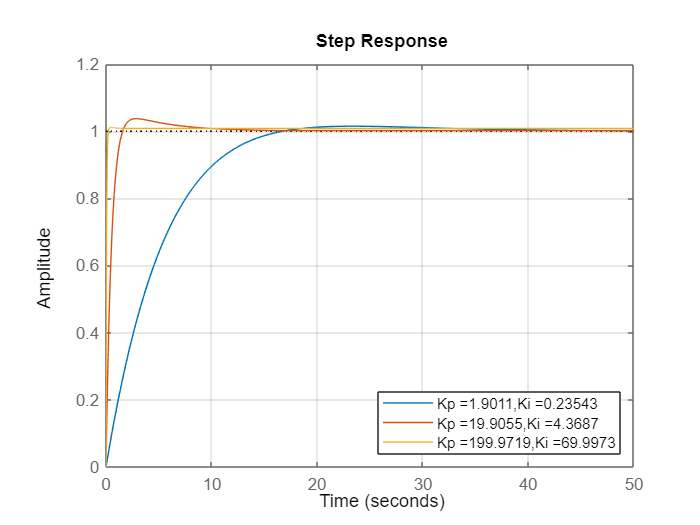

sysf1 = feedback(sys*PI1,1);
sysf2 = feedback(sys*PI2,1);
sysf3 = feedback(sys*PI3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+PI1.Kp+",Ki ="+PI1.Ki,"Kp ="+PI2.Kp+",Ki ="+PI2.Ki,"Kp ="+PI3.Kp+",Ki ="+PI3.Ki,'Location','southeast')
grid minor

Everything gets better as kp increases.

With the increase of ki, the settling time is low, the Steady State error is 0, but the overshoot percentage increases.

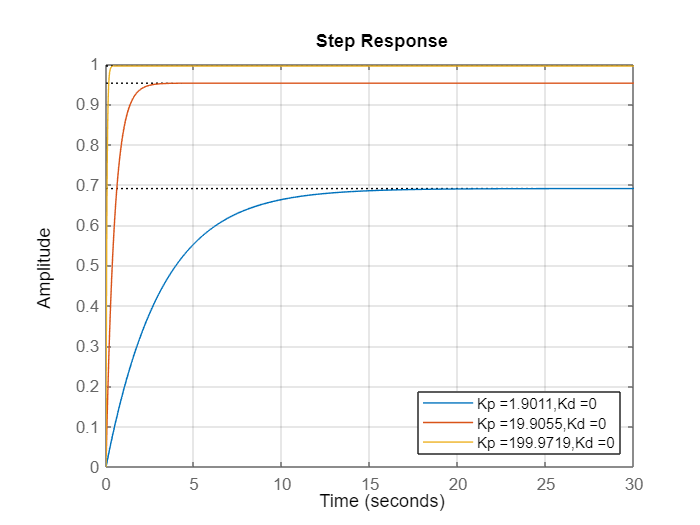

sysf1 = feedback(sys*PD1,1);
sysf2 = feedback(sys*PD2,1);
sysf3 = feedback(sys*PD3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+PI1.Kp+",Kd ="+PI1.Kd,"Kp ="+PI2.Kp+",Kd ="+PI2.Kd,"Kp ="+PI3.Kp+",Kd ="+PI3.Kd,'Location','southeast')
grid minor

Everything gets better as kp increases.

Toolbox recommends that kd be equal to 0.

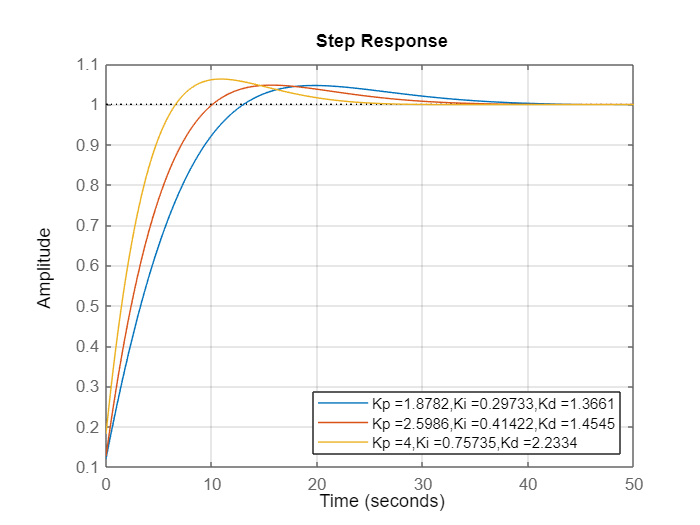

sysf1 = feedback(sys*PID1,1);
sysf2 = feedback(sys*PID2,1);
sysf3 = feedback(sys*PID3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+PID1.Kp+",Ki ="+PID1.Ki+",Kd ="+PID1.Kd,"Kp ="+PID2.Kp+",Ki ="+PID2.Ki+",Kd ="+PID2.Kd,"Kp ="+PID3.Kp+",Ki ="+PID3.Ki+",Kd ="+PID3.Kd,'Location','southeast')
grid minor

The Steady State error has been removed due to the presence of I, but in general, due to the change of all parameters, it is impossible to say anything.

## b)   $\frac{1}{s^2 +0\ldotp 1s+1}$

sys = tf([1],[1 0.1 1]);

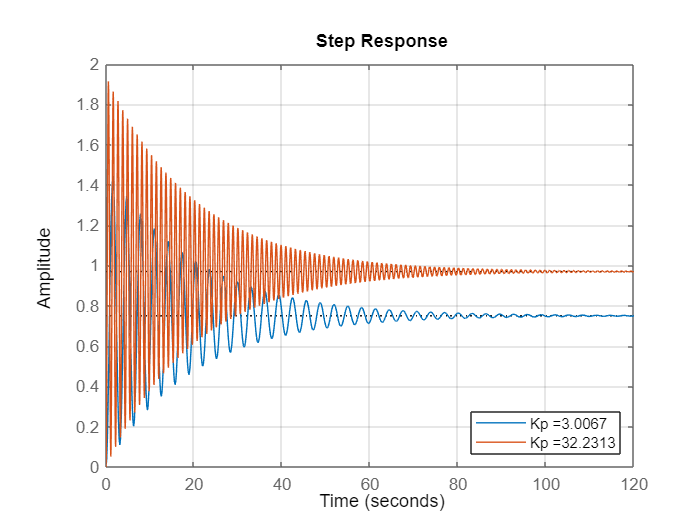

sysf1 = feedback(sys*P1,1);
sysf2 = feedback(sys*P2,1);
sysf3 = feedback(sys*P3,1);
step(sysf1,sysf2)
legend("Kp ="+P1.Kp,"Kp ="+P2.Kp,'Location','southeast')
grid minor

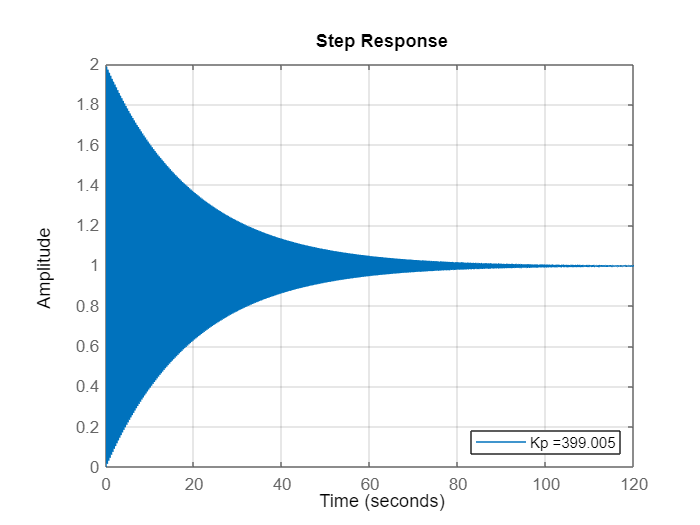

step(sysf3)
legend("Kp ="+P3.Kp,'Location','southeast')
grid minor

By changing kp, only the amplitude will change and we will still have overshoot, but with the increase of kp, we will have less settling time and less Steady State error.

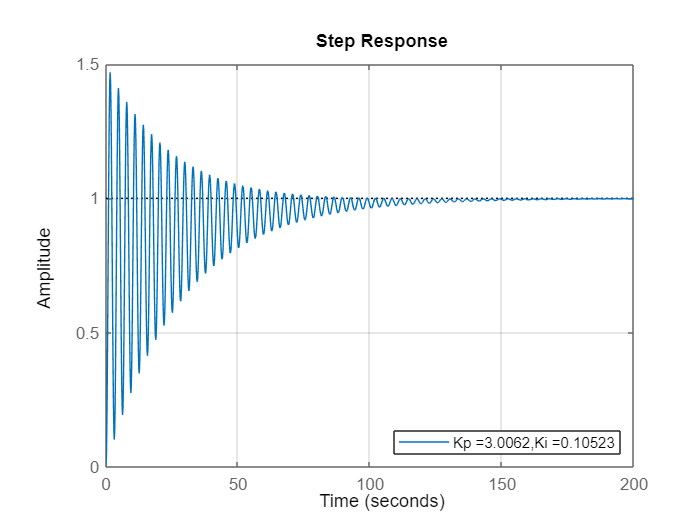

sysf1 = feedback(sys*PI1,1);
sysf2 = feedback(sys*PI2,1);
sysf3 = feedback(sys*PI3,1);
step(sysf1)
legend("Kp ="+PI1.Kp+",Ki ="+PI1.Ki,'Location','southeast')
grid minor

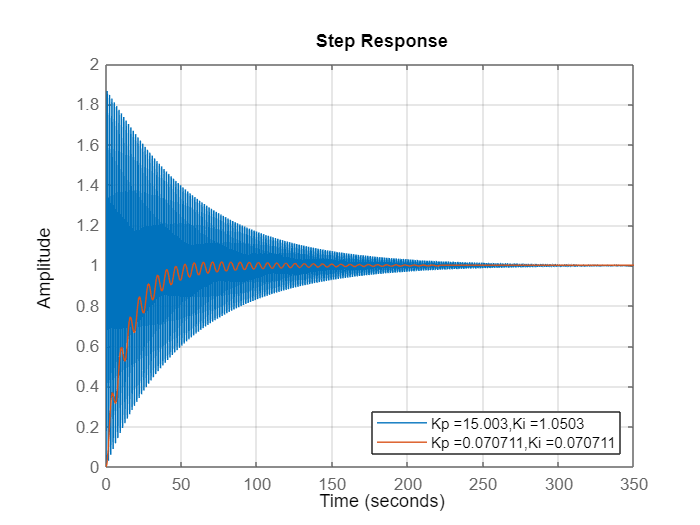

step(sysf2,sysf3)
legend("Kp ="+PI2.Kp+",Ki ="+PI2.Ki,"Kp ="+PI3.Kp+",Ki ="+PI3.Ki,'Location','southeast')
grid minor

With the increase of Kp,Ki, the settling time and the overshoot percentage and the settling time increase. TheSteady State error is 0.

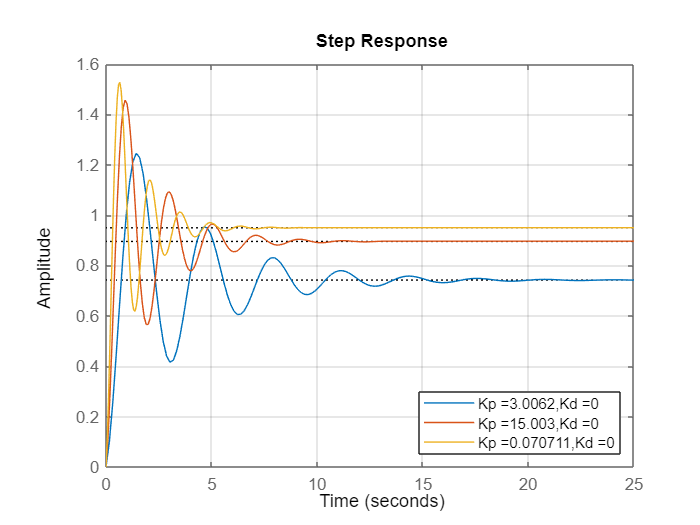

sysf1 = feedback(sys*PD1,1);
sysf2 = feedback(sys*PD2,1);
sysf3 = feedback(sys*PD3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+PI1.Kp+",Kd ="+PI1.Kd,"Kp ="+PI2.Kp+",Kd ="+PI2.Kd,"Kp ="+PI3.Kp+",Kd ="+PI3.Kd,'Location','southeast')
grid minor

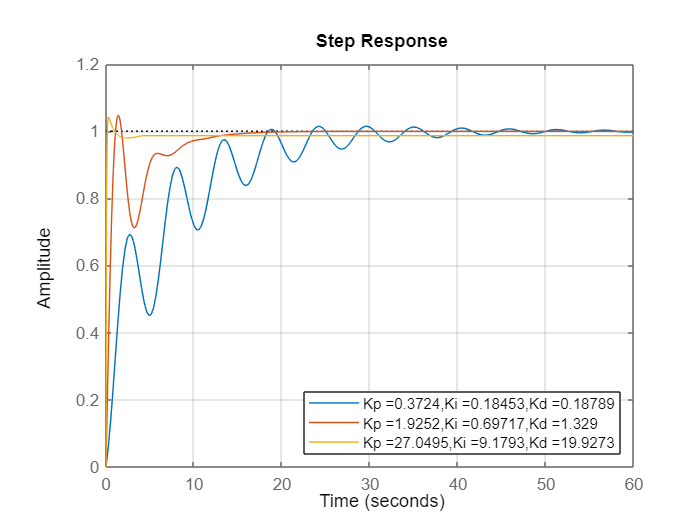

sysf1 = feedback(sys*PID1,1);
sysf2 = feedback(sys*PID2,1);
sysf3 = feedback(sys*PID3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+PID1.Kp+",Ki ="+PID1.Ki+",Kd ="+PID1.Kd,"Kp ="+PID2.Kp+",Ki ="+PID2.Ki+",Kd ="+PID2.Kd,"Kp ="+PID3.Kp+",Ki ="+PID3.Ki+",Kd ="+PID3.Kd,'Location','southeast')
grid minor

With the increase of the coefficients, especially kd, the overshoot is greatly reduced and the settling time is also reduced

## C)  $\;\frac{1}{s\left(s^2 +0\ldotp 1s+1\right)}$

sys = tf([1],[1 0.1 1]);

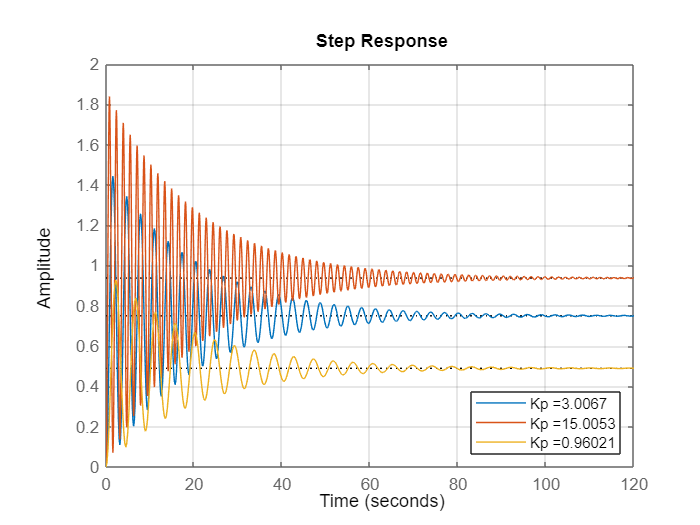

sysf1 = feedback(sys*P1,1);
sysf2 = feedback(sys*P2,1);
sysf3 = feedback(sys*P3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+P1.Kp,"Kp ="+P2.Kp,"Kp ="+P3.Kp,'Location','southeast')
grid minor

With the increase of kp, the Steady State error is less, the overshoot is more and the settling time does not change.

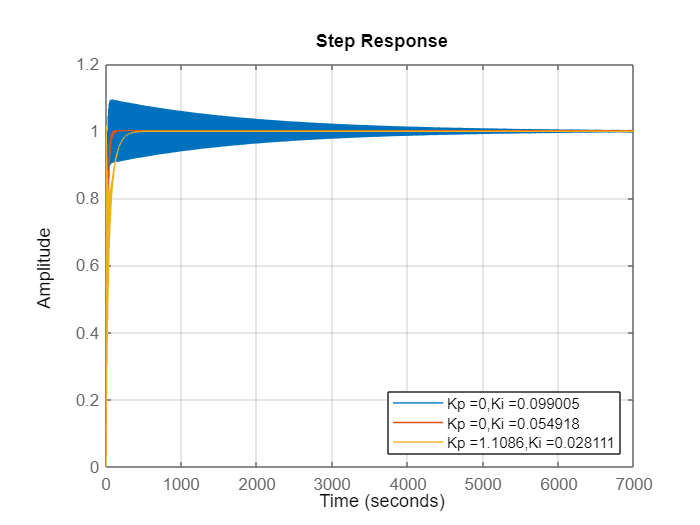

sysf1 = feedback(sys*PI1,1);
sysf2 = feedback(sys*PI2,1);
sysf3 = feedback(sys*PI3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+PI1.Kp+",Ki ="+PI1.Ki,"Kp ="+PI2.Kp+",Ki ="+PI2.Ki,"Kp ="+PI3.Kp+",Ki ="+PI3.Ki,'Location','southeast')
grid minor

With the increase of Ki, the overshoot increases, but the permanent error is equal to 0, and it also increases the settling time.

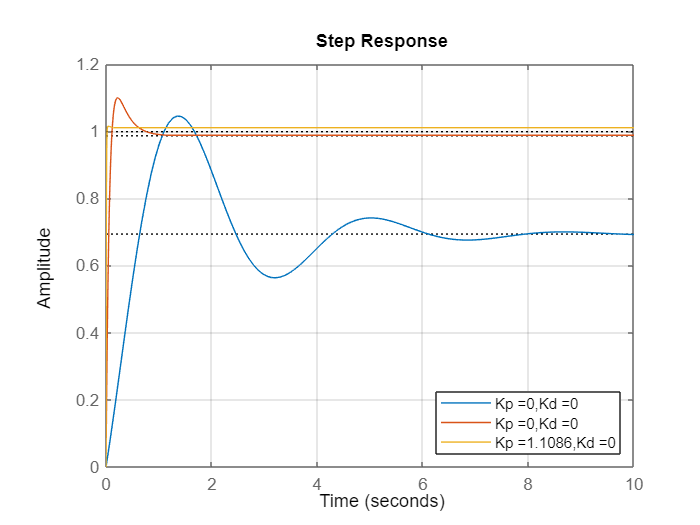

sysf1 = feedback(sys*PD1,1);
sysf2 = feedback(sys*PD2,1);
sysf3 = feedback(sys*PD3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+PI1.Kp+",Kd ="+PI1.Kd,"Kp ="+PI2.Kp+",Kd ="+PI2.Kd,"Kp ="+PI3.Kp+",Kd ="+PI3.Kd,'Location','southeast')
grid minor

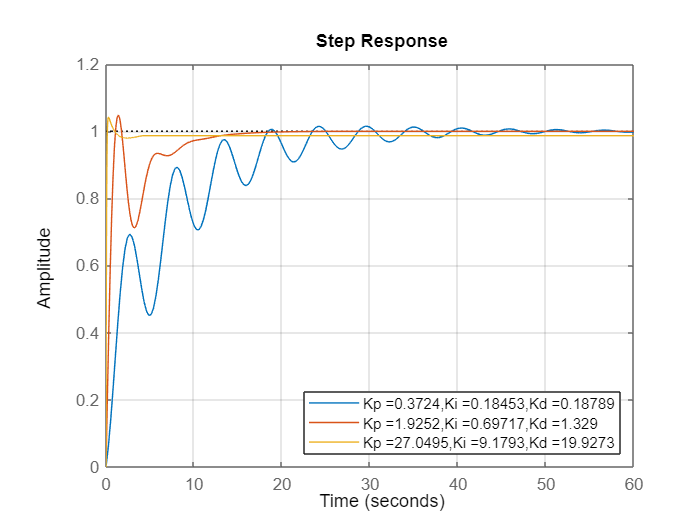

sysf1 = feedback(sys*PID1,1);
sysf2 = feedback(sys*PID2,1);
sysf3 = feedback(sys*PID3,1);
step(sysf1,sysf2,sysf3)
legend("Kp ="+PID1.Kp+",Ki ="+PID1.Ki+",Kd ="+PID1.Kd,"Kp ="+PID2.Kp+",Ki ="+PID2.Ki+",Kd ="+PID2.Kd,"Kp ="+PID3.Kp+",Ki ="+PID3.Ki+",Kd ="+PID3.Kd,'Location','southeast')
grid minor

With the increase of the coefficients, especially kd, the overshoot is greatly reduced and the settling time is also reduced.

In general we have:

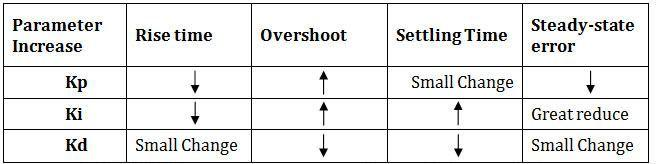

## d)$\;\frac{1}{s\left(s^4 -1\right)}$

We will see that two unstable poles cannot be stabilized by any method:

sys = tf([1],[1 0 0 0 1 0])

sys =
 
     1
  -------
  s^5 + s
 
Continuous-time transfer function.



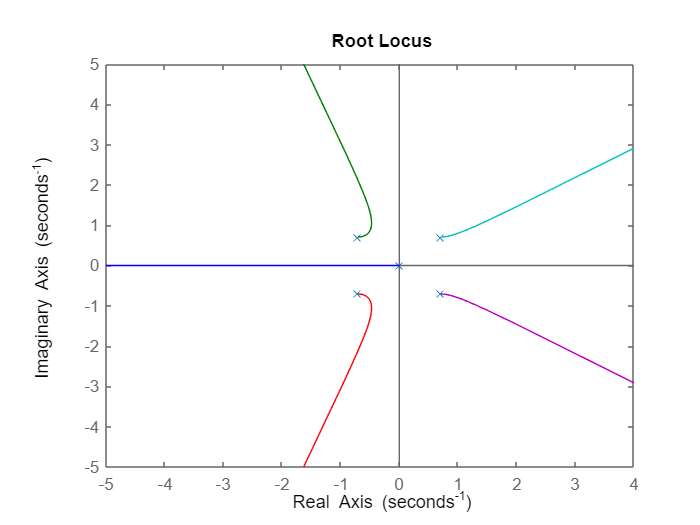

rlocus(sys)

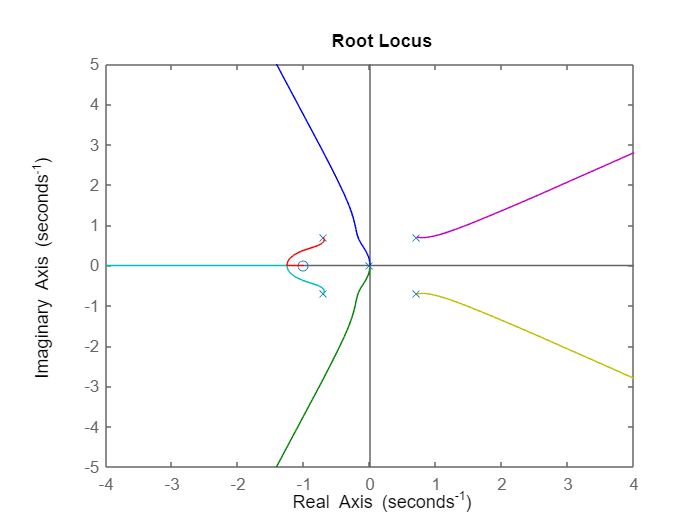

s = tf("s");
PI = (s+1)/s;
rlocus(sys*PI)

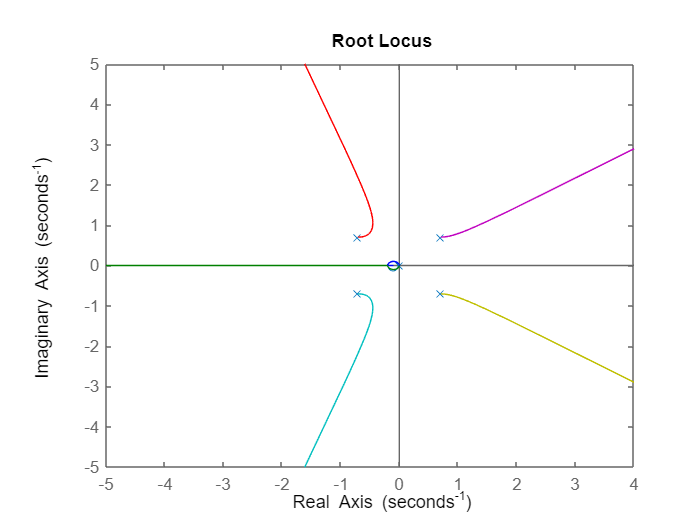

PI = (10*s+1)/s;
rlocus(sys*PI)

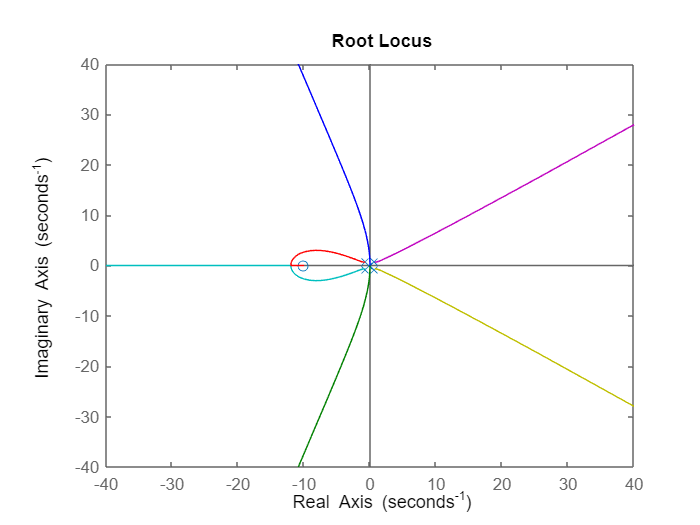

PI = (0.1*s+1)/s;
rlocus(sys*PI)

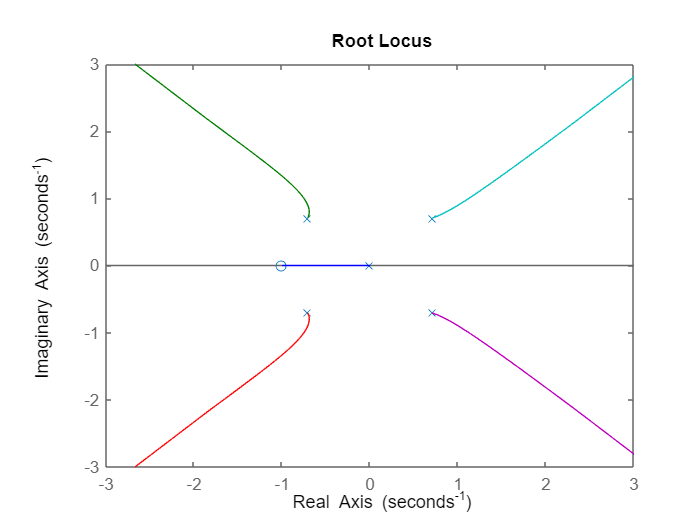

s = tf("s");
PD = (s+1);
rlocus(sys*PD)

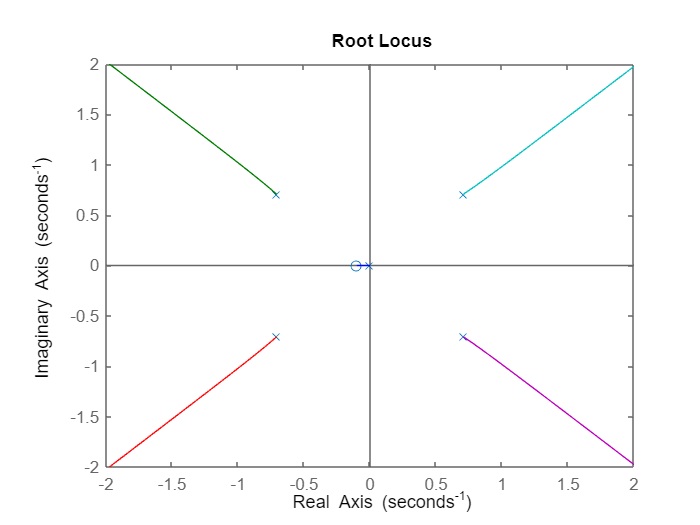

PD = (10*s+1);
rlocus(sys*PD)

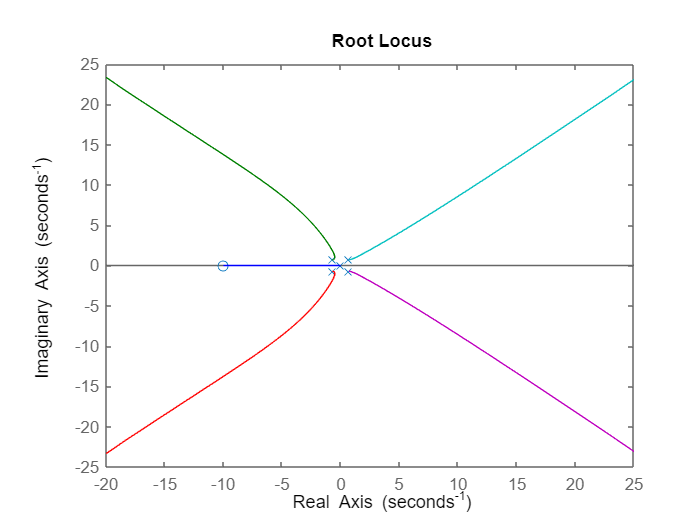

PD = (0.1*s+1);
rlocus(sys*PD)

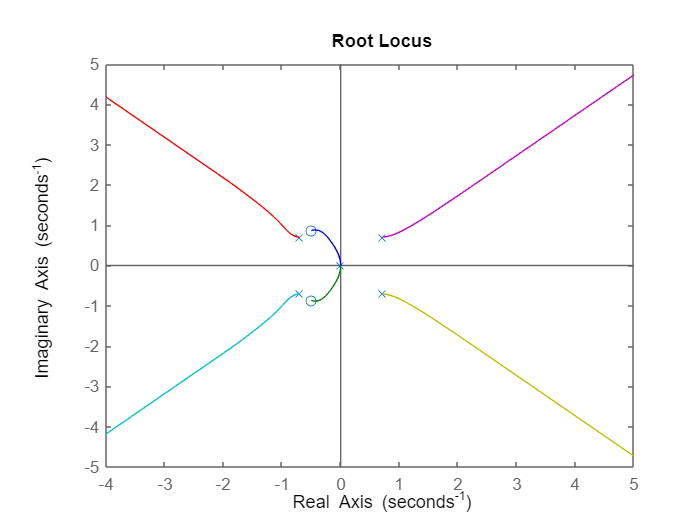

s = tf("s");
PID = 1 + 1*s + 1/s ;
rlocus(sys*PID)

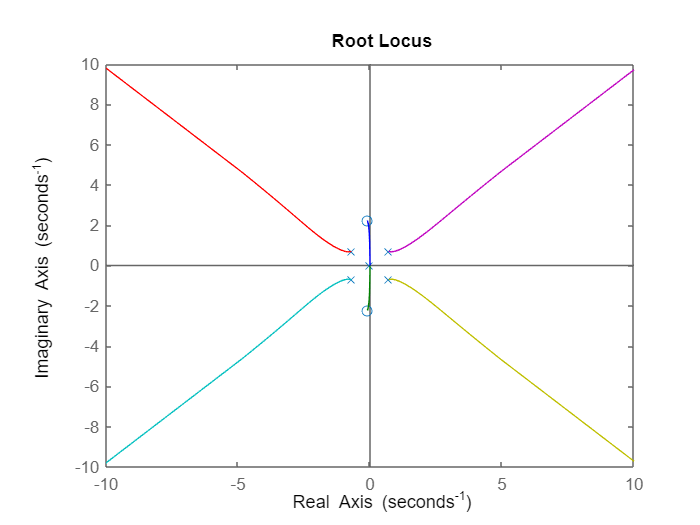

PID = 1 + 5*s + 25/s;
rlocus(sys*PID)

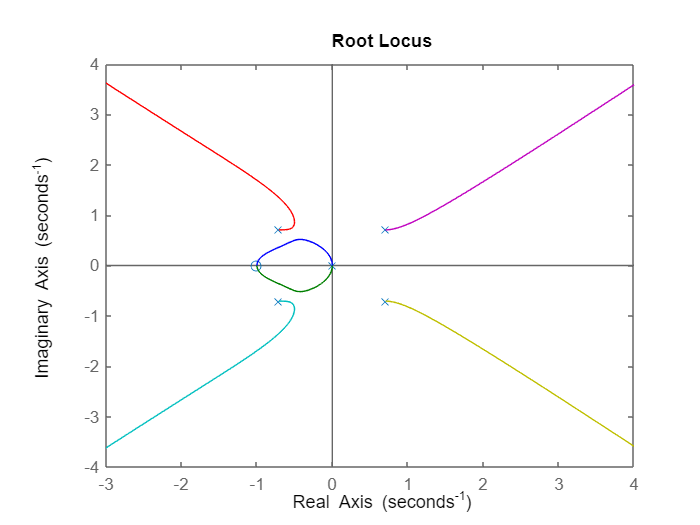

PID = 2 + 1*s + 1/s;
rlocus(sys*PID)

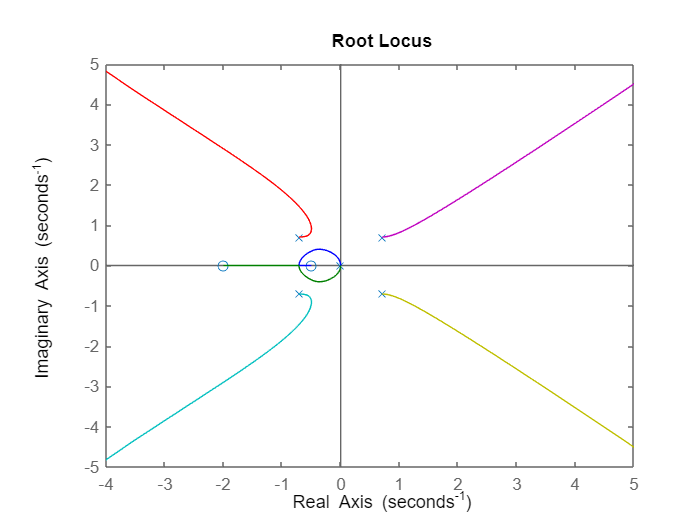

PID = 2.5 + 1*s + 1/s;
rlocus(sys*PID)

# 8 Cascade Control System

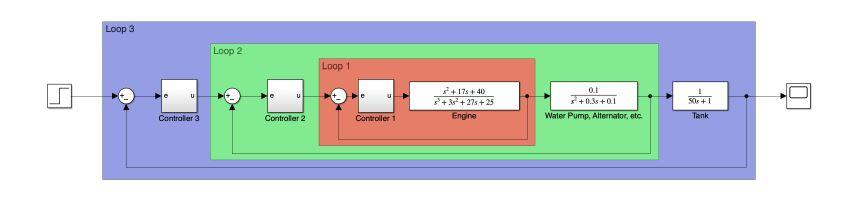

The PID controller was designed with PID tune toolbox in  MATLAB Simulink. In the first stage, the controller effort is tried to be between 0 and 1. The second and third steps are to ensure that $u_1$ is not out of range and the output is acceptable.

clc
clear all

s = tf("s");
Engine = (s^2+17*s+40)/(s^3 +3*s^2+27*s+25);
WaterPump = 0.1/(s^2+0.3*s+0.1);
Tank = 1/(50*s+1);

## a)

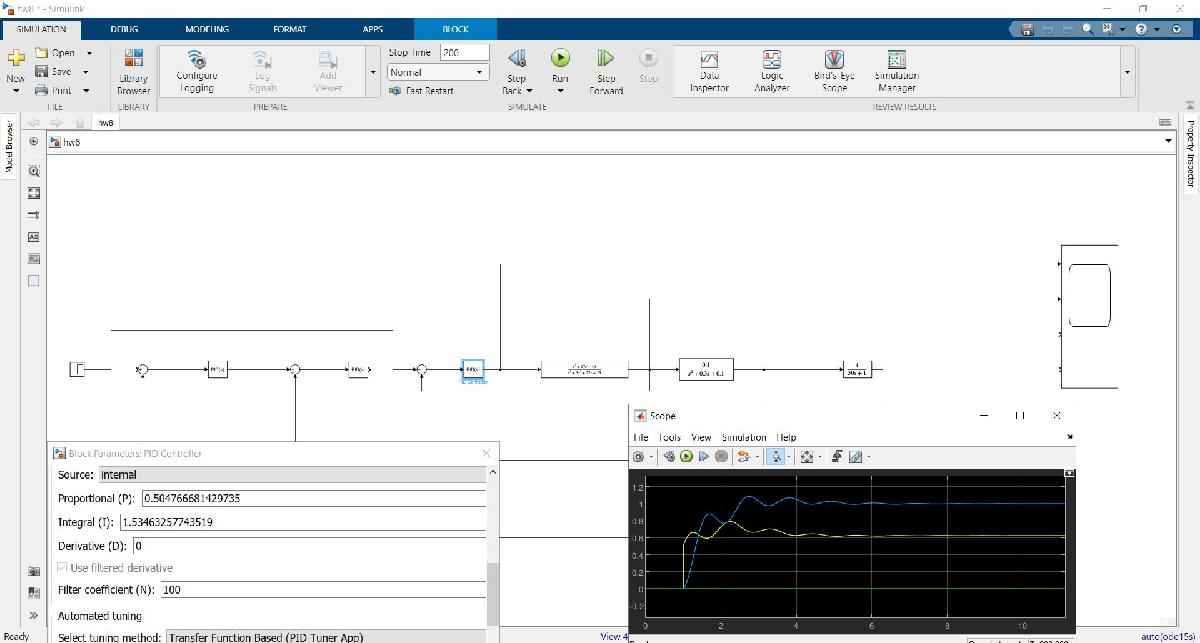

Con1 = 0.5048 + 1.535/s;
sf1 = feedback(Engine*Con1,1);

## b)

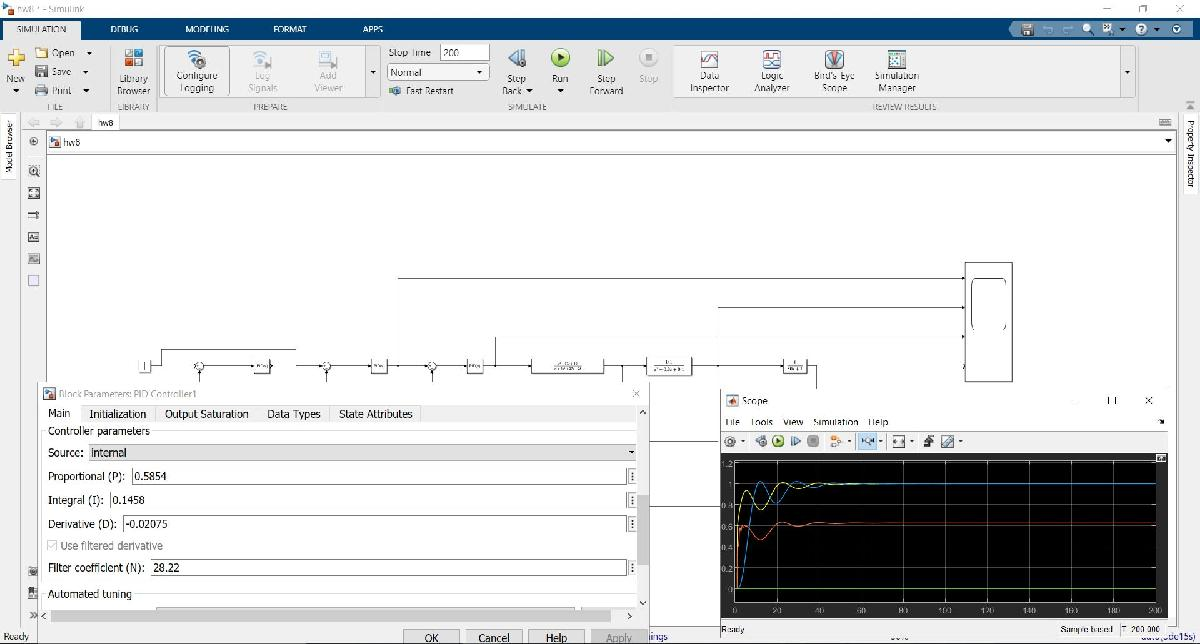

loop2sys = sf1*WaterPump;
Con2 = 0.5854 + 0.1458/s -0.02075*(28.2/(1+28.22/s));
sf2 = feedback(loop2sys*Con2,1);

## c)

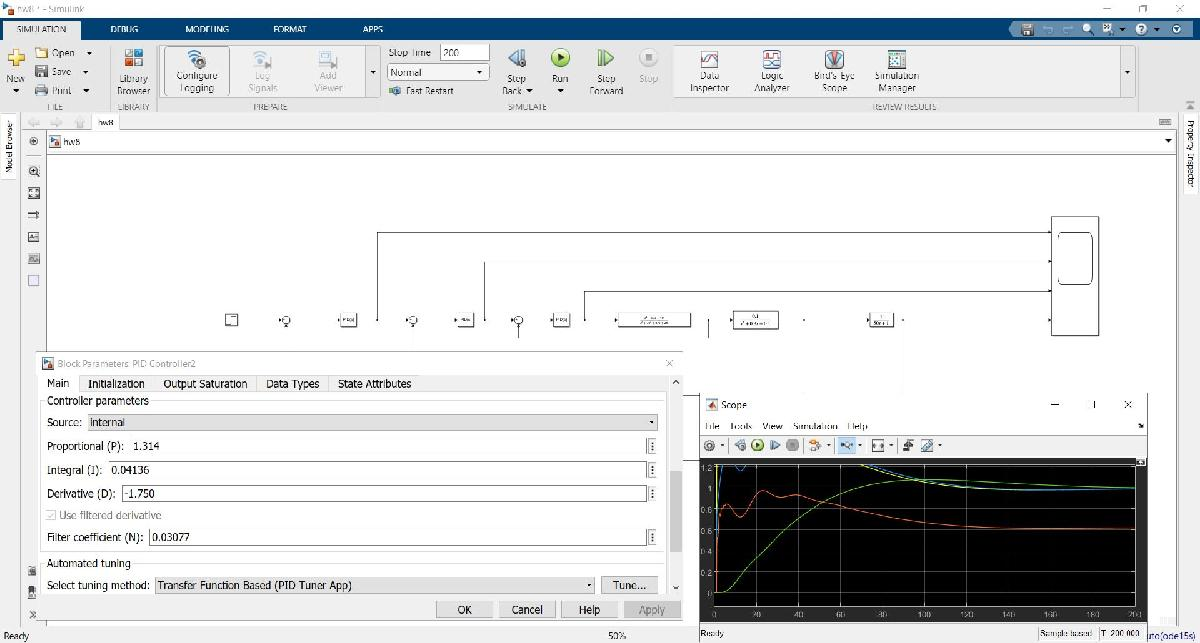

loop3sys = sf2*Tank;
Con3 = 1.314 + 0.04136/s -1.750*(0.03077/(1+0.03077/s));
sf3 = feedback(loop3sys*Con3,1);

## d)

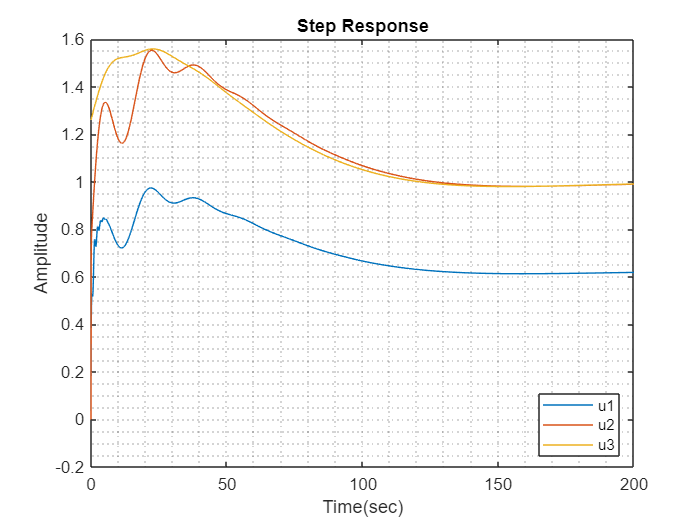

plot(out.tout,out.u1.Data,out.tout,out.u2.Data,out.tout,out.u3.Data)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("u1","u2","u3","Location","best")
grid minor

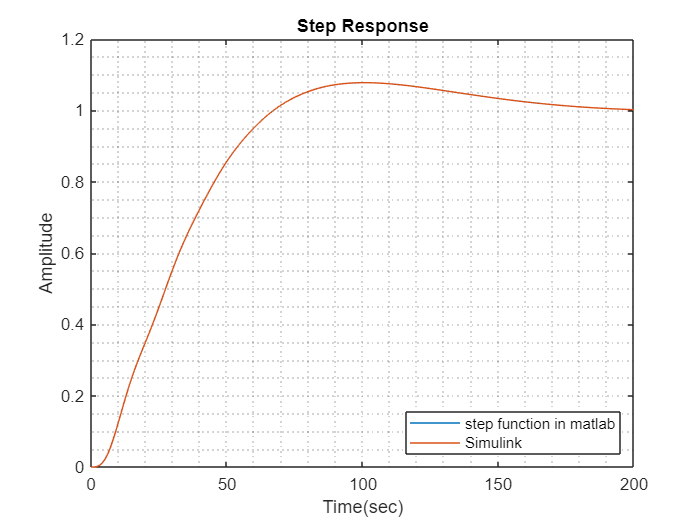

[yy tt] = step(sf3,200);
plot(tt ,yy,out.tout,out.y.Data)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("step function in matlab","Simulink","Location","southeast")
grid minor

stepinfo(sf3)

ans = struct with fields:
         RiseTime: 45.0467
    TransientTime: 164.5381
     SettlingTime: 164.5381
      SettlingMin: 0.9081
      SettlingMax: 1.0776
        Overshoot: 7.7573
       Undershoot: 0
             Peak: 1.0776
         PeakTime: 101.0054


## e)

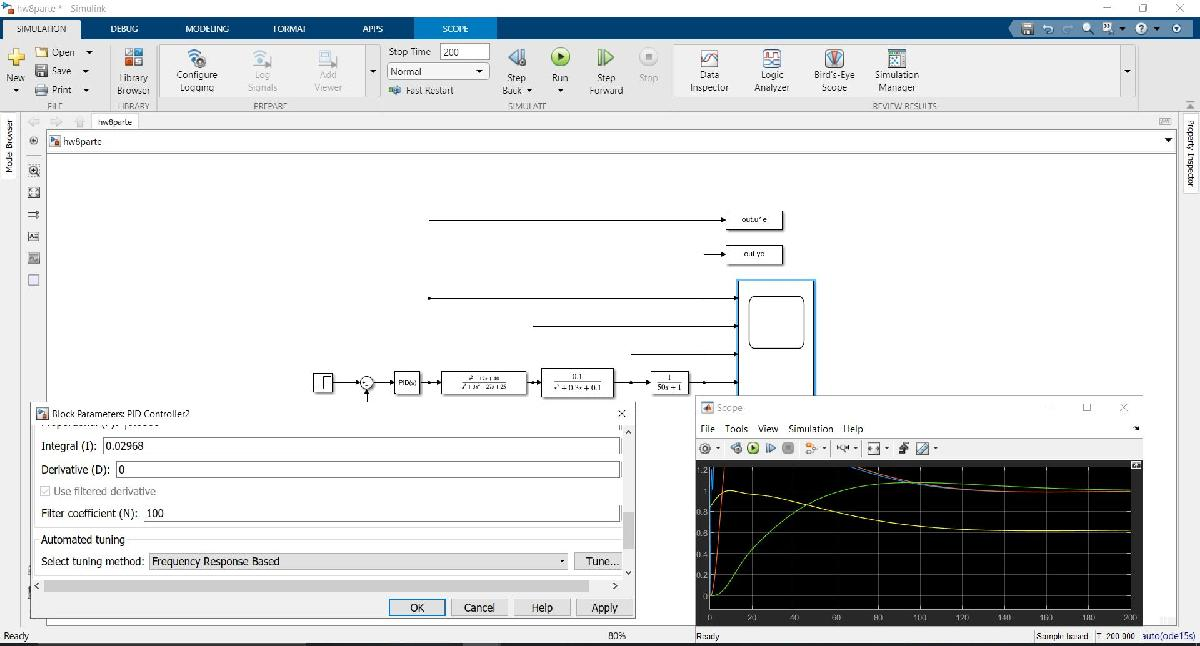

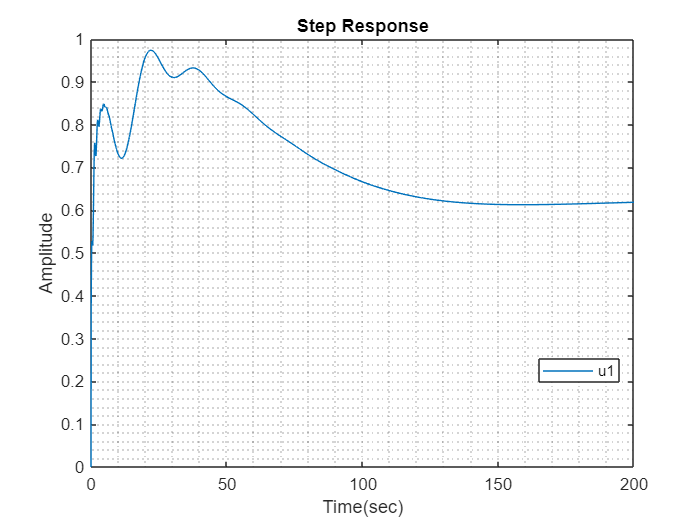

syse = Engine*WaterPump*Tank;
Cone = 0.8388+0.02968/s;
sfe = feedback(syse*Cone,1);
plot(out.tout,out.u1.Data)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("u1","Location","best")
grid minor

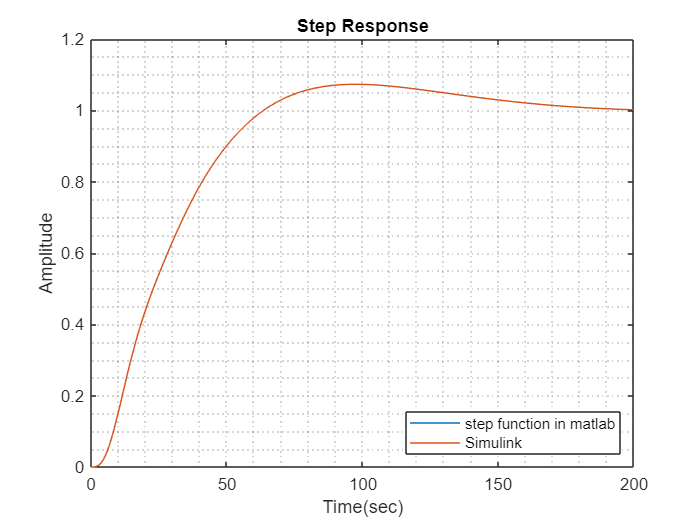


[yye, tte] = step(sfe,200);
plot(tte ,yye,out.tout,out.ye.Data)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("step function in matlab","Simulink","Location","southeast")
grid minor

## f)

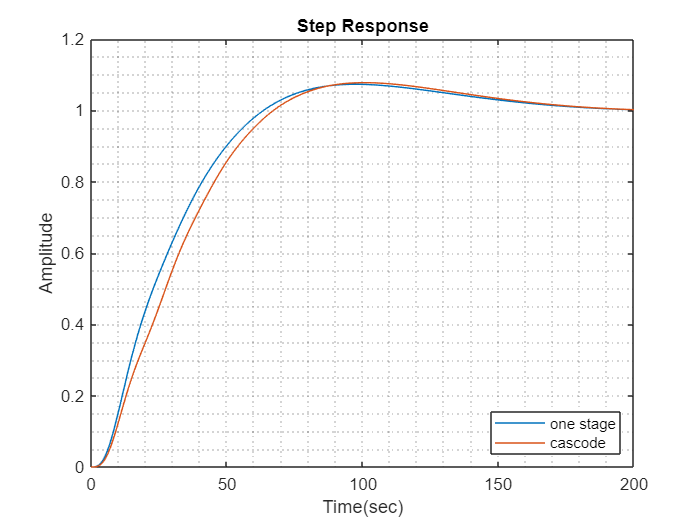

plot(tte ,yye,tt ,yy)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("one stage","cascode","Location","southeast")
grid minor

It seems that the efficiency of casecode is much better than conventional, but due to the many parameters in casecode, conventional design is better (due to the lack of experience of the designer).

# 9 Reducing The Effect of Measurement Noise

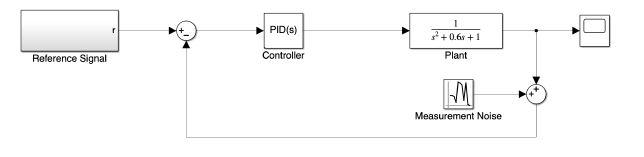

## a)

By using pid tuner and changing the speed slider, we reach the desired question:

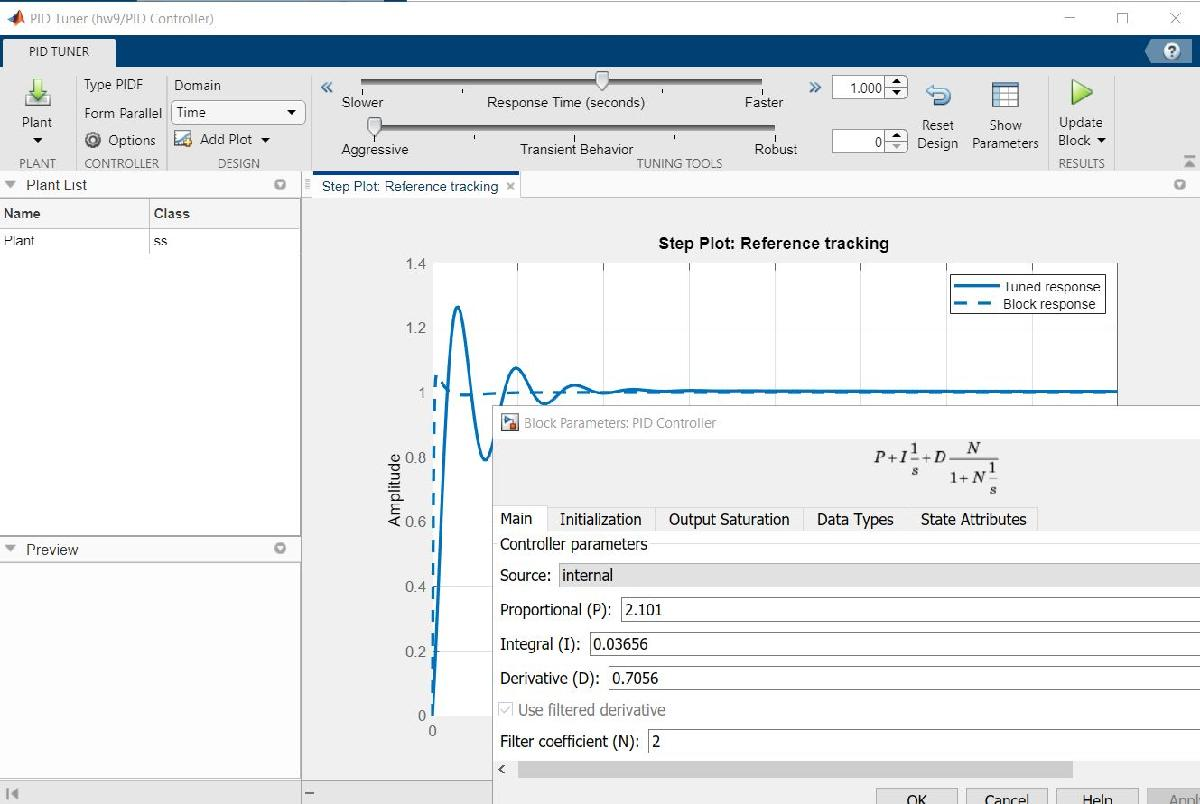

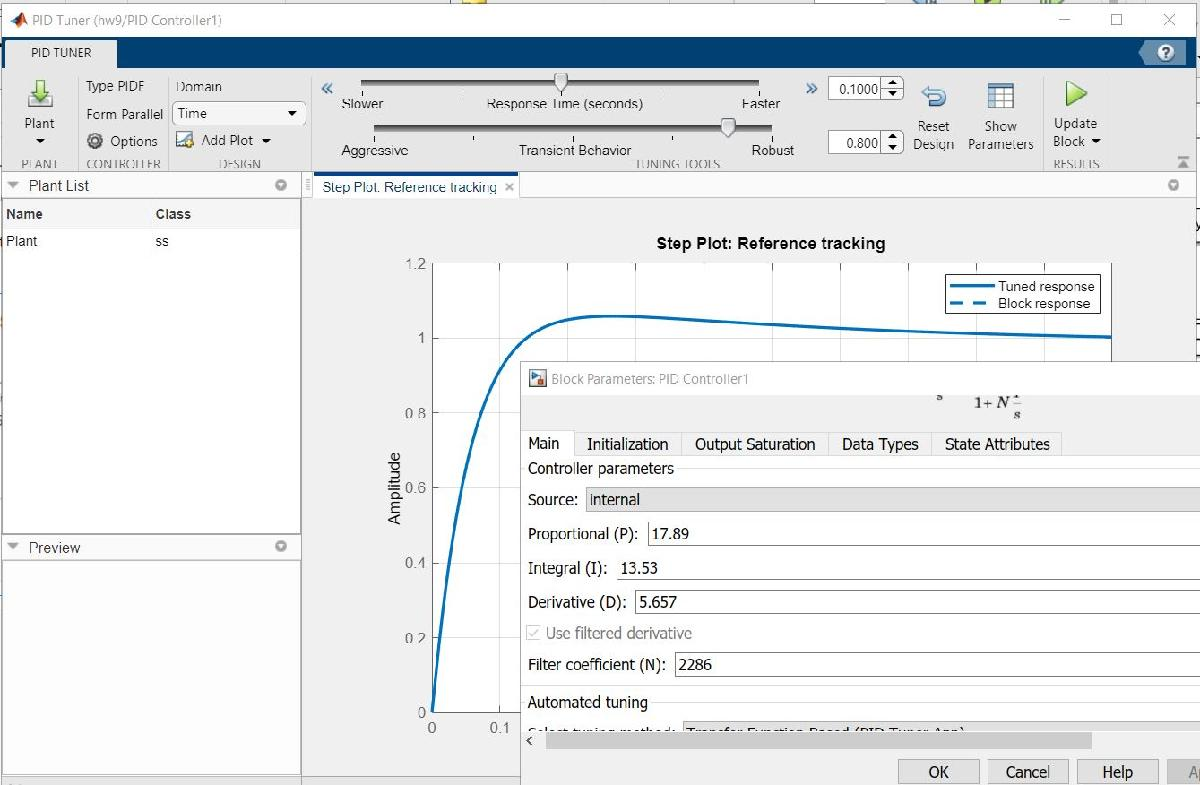

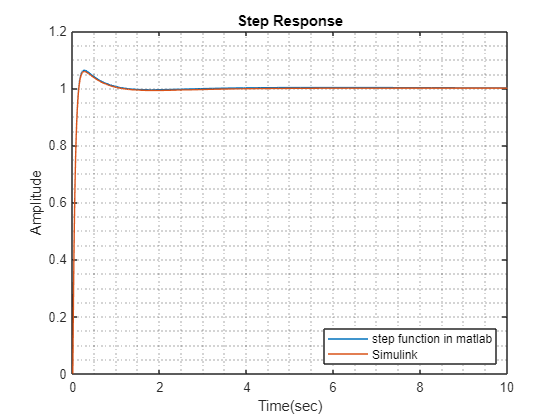

s = tf("s");
plant =1/(s^2+0.6*s+1);
PID1_zero = 2.101+0.3656/s+0.7056*(2/(1+2/s));
PID1_robust = 17.89+13.53/s+5.657*(2286/(1+2286/s));
sysf9 = feedback(plant*PID1_zero*PID1_robust,1);
[y9,t9] = step(sysf9,10);
plot(t9 ,y9,out.tout,out.y9o.Data)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("step function in matlab","Simulink","Location","southeast")
grid minor

stepinfo(sysf9)

ans = struct with fields:
         RiseTime: 0.0891
    TransientTime: 0.7187
     SettlingTime: 0.7187
      SettlingMin: 0.9092
      SettlingMax: 1.0631
        Overshoot: 6.3067
       Undershoot: 0
             Peak: 1.0631
         PeakTime: 0.2666


The effect of noise on the output:

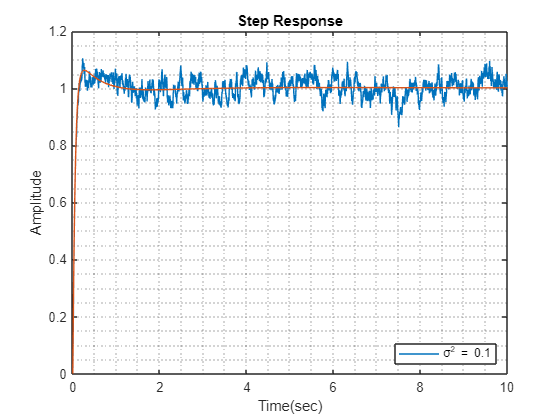

plot(out.tout,out.y9oo1.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.1","Location","southeast")
grid minor

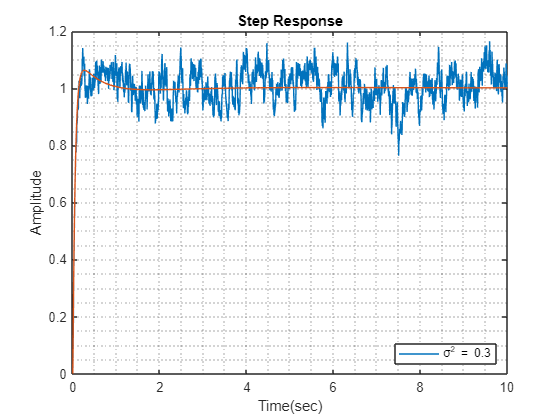

plot(out.tout,out.y9oo3.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.3","Location","southeast")
grid minor

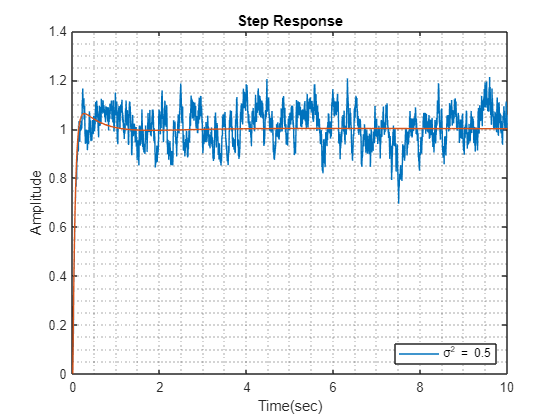

plot(out.tout,out.y9oo5.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.5","Location","southeast")
grid minor

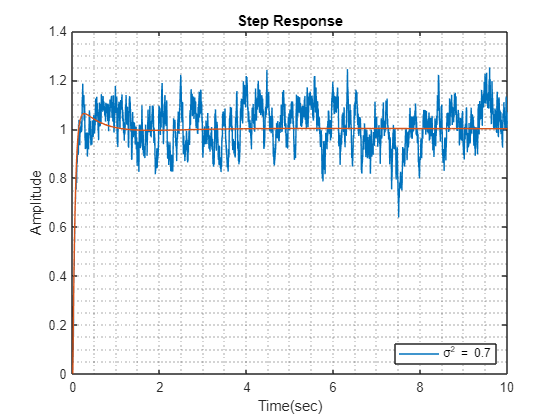

plot(out.tout,out.y9oo7.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.7","Location","southeast")
grid minor

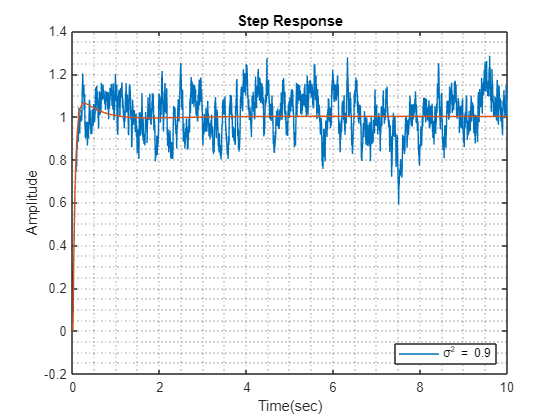

plot(out.tout,out.y9oo9.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.9","Location","southeast")
grid minor

As expected, the high frequency noises are weakened, but the noise remains in the working frequency range.

## b)

The cutoff frequency is equal to 1 rad/s, so a filter with this bandwidth and a little less can be very useful:

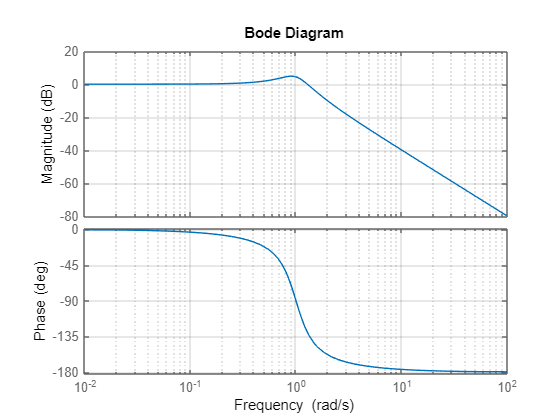

s = tf("s");
plant =1/(s^2+0.6*s+1);
bode(plant)
grid minor

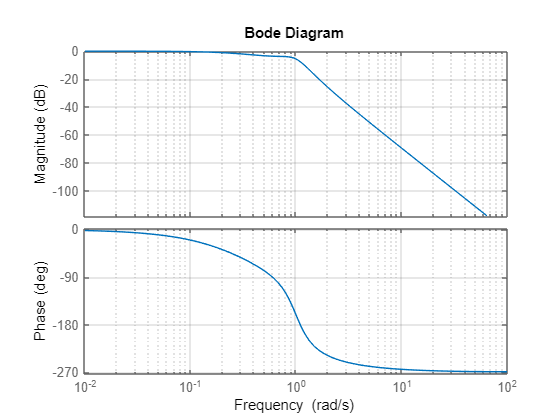

LOWPAss = 1/(3*s+1);
bode(LOWPAss*plant)
grid minor

### Expected

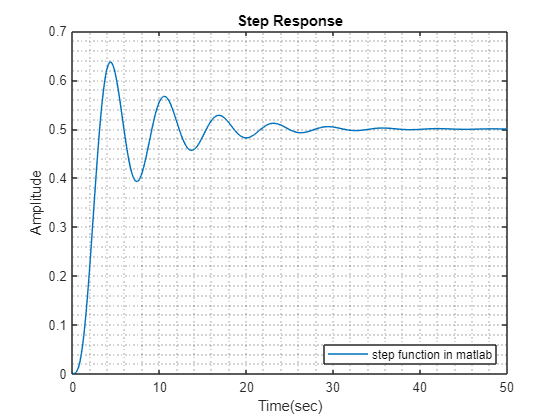

sysf9b = feedback(LOWPAss*plant,1);
[y9,t9] = step(sysf9b,50);
plot(t9 ,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("step function in matlab","Location","southeast")
grid minor

stepinfo(sysf9b)

ans = struct with fields:
         RiseTime: 1.8015
    TransientTime: 23.6569
     SettlingTime: 23.6569
      SettlingMin: 0.3927
      SettlingMax: 0.6372
        Overshoot: 27.4338
       Undershoot: 0
             Peak: 0.6372
         PeakTime: 4.3587


### Noisy outpots

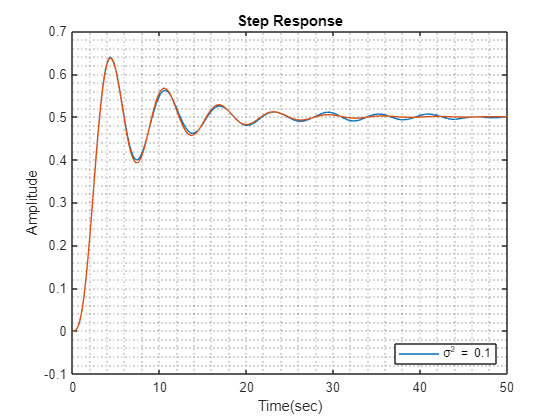

plot(out.tout,out.y9o1.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.1","Location","southeast")
grid minor

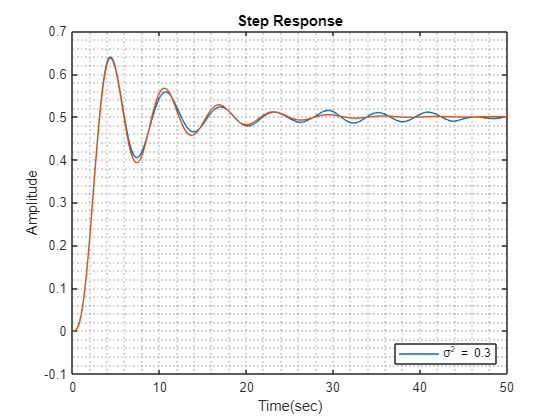

plot(out.tout,out.y9o3.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.3","Location","southeast")
grid minor

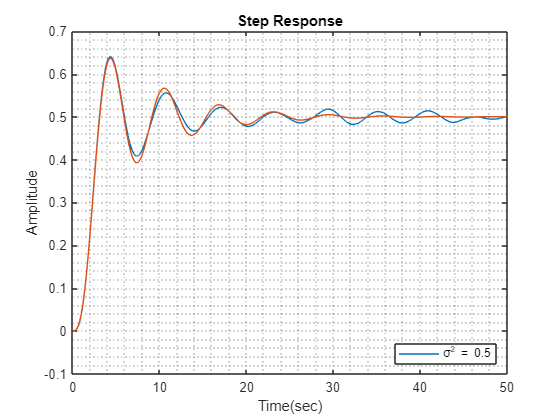

plot(out.tout,out.y9o5.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.5","Location","southeast")
grid minor

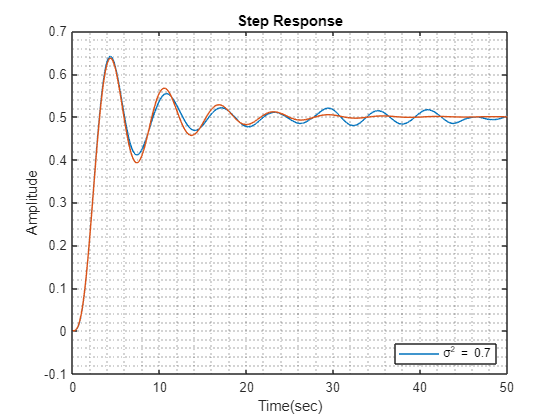

plot(out.tout,out.y9o7.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.7","Location","southeast")
grid minor

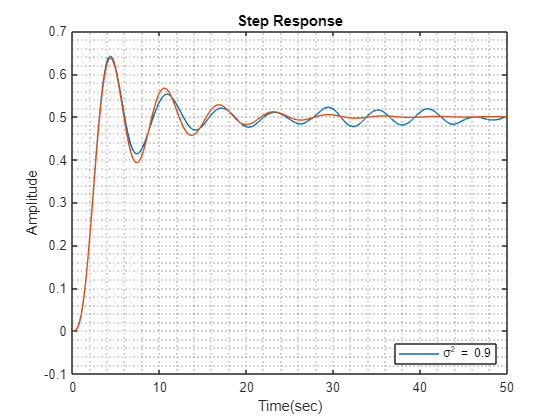

plot(out.tout,out.y9o9.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.9","Location","southeast")
grid minor

## c)

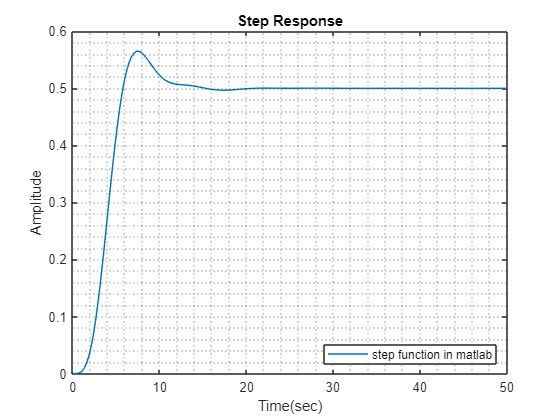

s = tf("s");
plant =1/(s^2+0.6*s+1);
LOWPAss = 1/(3*s+1)^2;
sysf9b = feedback(LOWPAss*plant,1);
[y9,t9] = step(sysf9b,50);
plot(t9 ,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("step function in matlab","Location","southeast")
grid minor

stepinfo(sysf9b)

ans = struct with fields:
         RiseTime: 3.1203
    TransientTime: 11.1837
     SettlingTime: 11.1837
      SettlingMin: 0.4606
      SettlingMax: 0.5651
        Overshoot: 13.0145
       Undershoot: 0
             Peak: 0.5651
         PeakTime: 7.4060


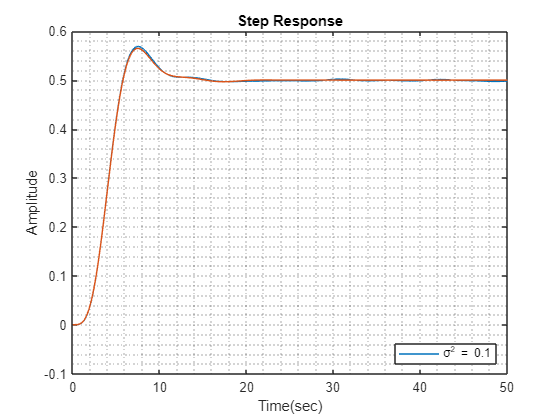


plot(out.tout,out.y9o1.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.1","Location","southeast")
grid minor

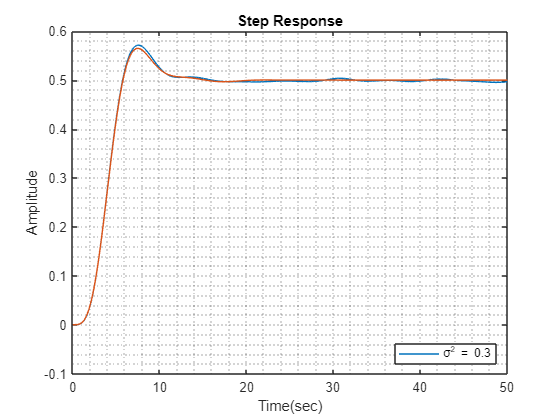

plot(out.tout,out.y9o3.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.3","Location","southeast")
grid minor

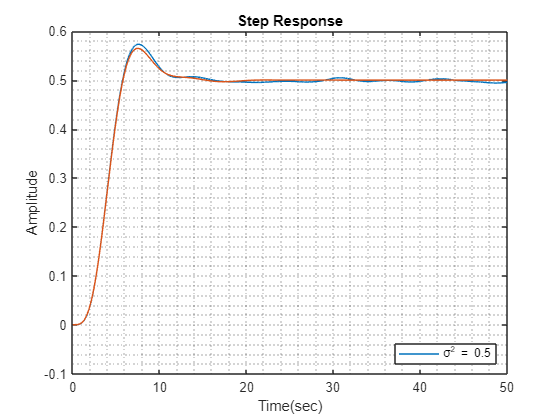

plot(out.tout,out.y9o5.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.5","Location","southeast")
grid minor

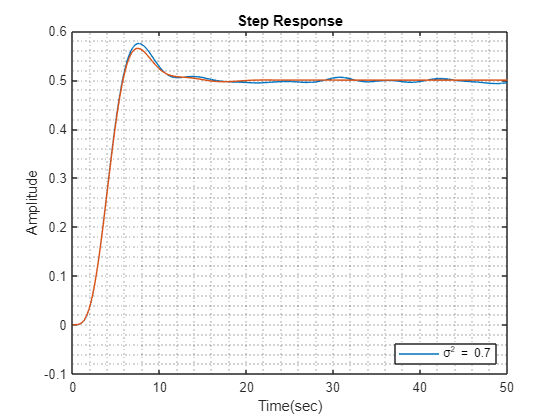

plot(out.tout,out.y9o7.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.7","Location","southeast")
grid minor

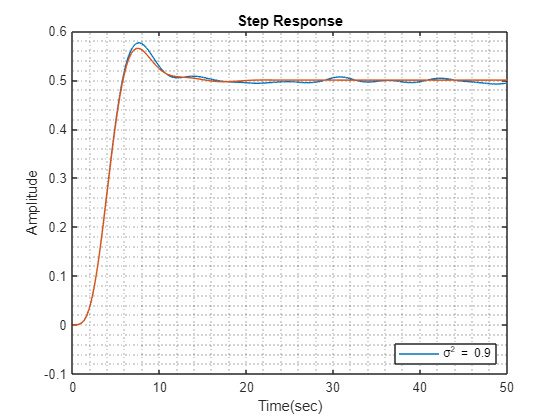

plot(out.tout,out.y9o9.Data,t9,y9)
title("Step Response")
ylabel("Amplitude")
xlabel("Time(sec)")
legend("\sigma^2 = 0.9","Location","southeast")
grid minor

function [u] = Step(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>=0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end